# 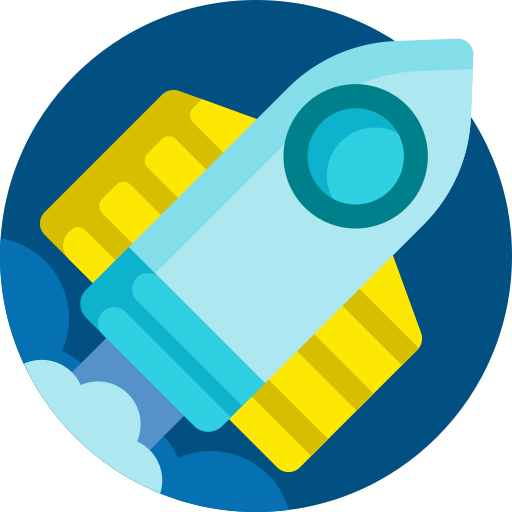 

# **MEC3079S: Control Systems**

# Chapter 6 — System characterisation

## 6.1 Introduction

Recall that transfer function, $P(s)$, can be written as a ratio of polynomials

$P(s)=\frac{a_0+a_1s+a_2s^2+...+a_ms^m}{b_0+b_1s+b_2s^2+...+b_ns^n}=\frac{N(s)}{D(s)}$,

where $\{a_i,b_i\}\in \mathbb{R}$ (the coefficients are real numbers) and $n\geq m$ (the denominator polynomial has equivalent or higher order than the numerator polynomial). Using factorization, $P(s)$ can be rewritten as a ratio of irreducible polynomials


$$\begin{array}{ll}
P(s) &= A \frac{ (s-z_1)(s-z_2) \ldots (s-z_m) }{ (s-p_1)(s-p_2) \ldots (s-p_n)}, \\
&= A\frac{\prod_{i=1}^m (s-z_i)}{\prod_{i=1}^n (s-p_i)},
\end{array}$$


where 

- the $z_i\in\mathbb{C}$ terms are the roots of the equation $N(s)=0$, which we refer to as the system zeros, and 

- the $p_i\in\mathbb{C}$ terms are the roots of the equation $D(s)=0$, which we refer to as the system poles. 

We will now begin to characterise elementary (low-order) systems by relating their respective pole and zero locations to the system's output response in the time-domain.

### 6.1.2 Poles and zeros of a first-order system

Consider the output response below of

$Y(s)=P(s)U(s)=\frac{s-z}{s(s-p)}$,

where $U(s)=\frac{1}{s}$ is a unit step input, and $P(s)=\frac{s-z}{s-p}$ is a first-order system with a single pole and zero. Based on our definition of poles and zeros, $P(s)$ has a pole at $s=p$, and a zero at $s=z$. Using partial fraction expansion

$Y(s)=\frac{s-z}{s(s-p)}=\frac{A}{s}+\frac{B}{s-p}=\frac{z/p}{s}+\frac{1-z/p}{s-p}$.

Based on the Laplace transform table, the system output response follows as

$y(t)=\frac{z}{p}+\left(1-\frac{z}{p}\right)e^{pt}$.

We can analyse the effects of different combinations of $z$ and $p$ in the s-plane and time domain using the following code. Specifically, our output is the step response, $y(t)$, shown on one the first figure, and the pole-zero map of $Y(s)$ is shown on the other figure.

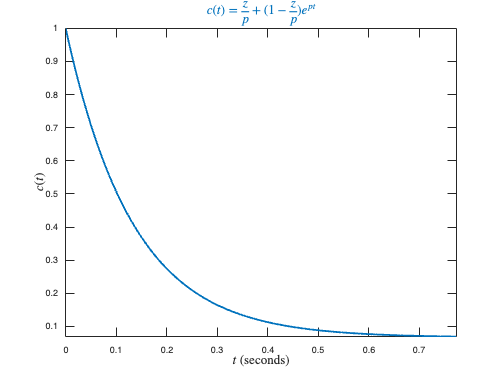

clear 
s=tf('s');

z = -0.5;
p = -7.5;
P = (s-z)/(s-p);
figure
[y,t] = step(P);
plot(t,y,lineWidth=2)
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$c(t)$',Interpreter='latex',FontSize=15)
title('$c(t)=\frac{z}{p}+(1-\frac{z}{p})e^{pt}$',Interpreter='latex',FontSize=15,Color='#0072BD')
axis tight

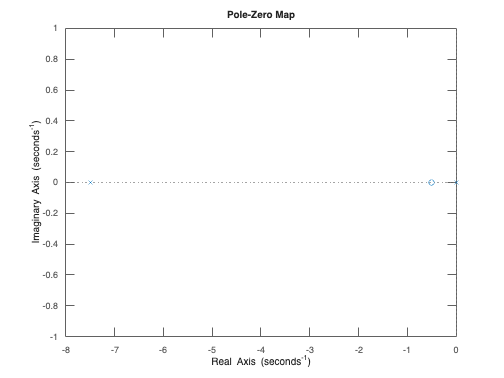

figure
pzmap(P/s) 

From the above example, we draw the following conclusions:

- The pole from the input function, from $U(s)=1/s$, generates the form of the *forced response.*

- The pole of the transfer function generates the form of the *natural response* (i.e., the pole at $s=p$ generated $\lambda e^{pt}$).

- A pole on the real axis generates an *exponential* response of the form $e^{p t}$, where $p$ is the pole location on the real axis. Thus, the farther to the left a pole is on the negative real axis, the faster the exponential transient response will decay to zero.

- The zeros and poles collectively generate the *amplitudes* for both the forced and natural responses (this can be seen from the calculation of $A$ and $B$ above).

- If the pole of $P(s)$ is in the closed right half-plane ($p\geq0$), then the output response grows without bound. Hence $P(s)$ is not strictly stable.

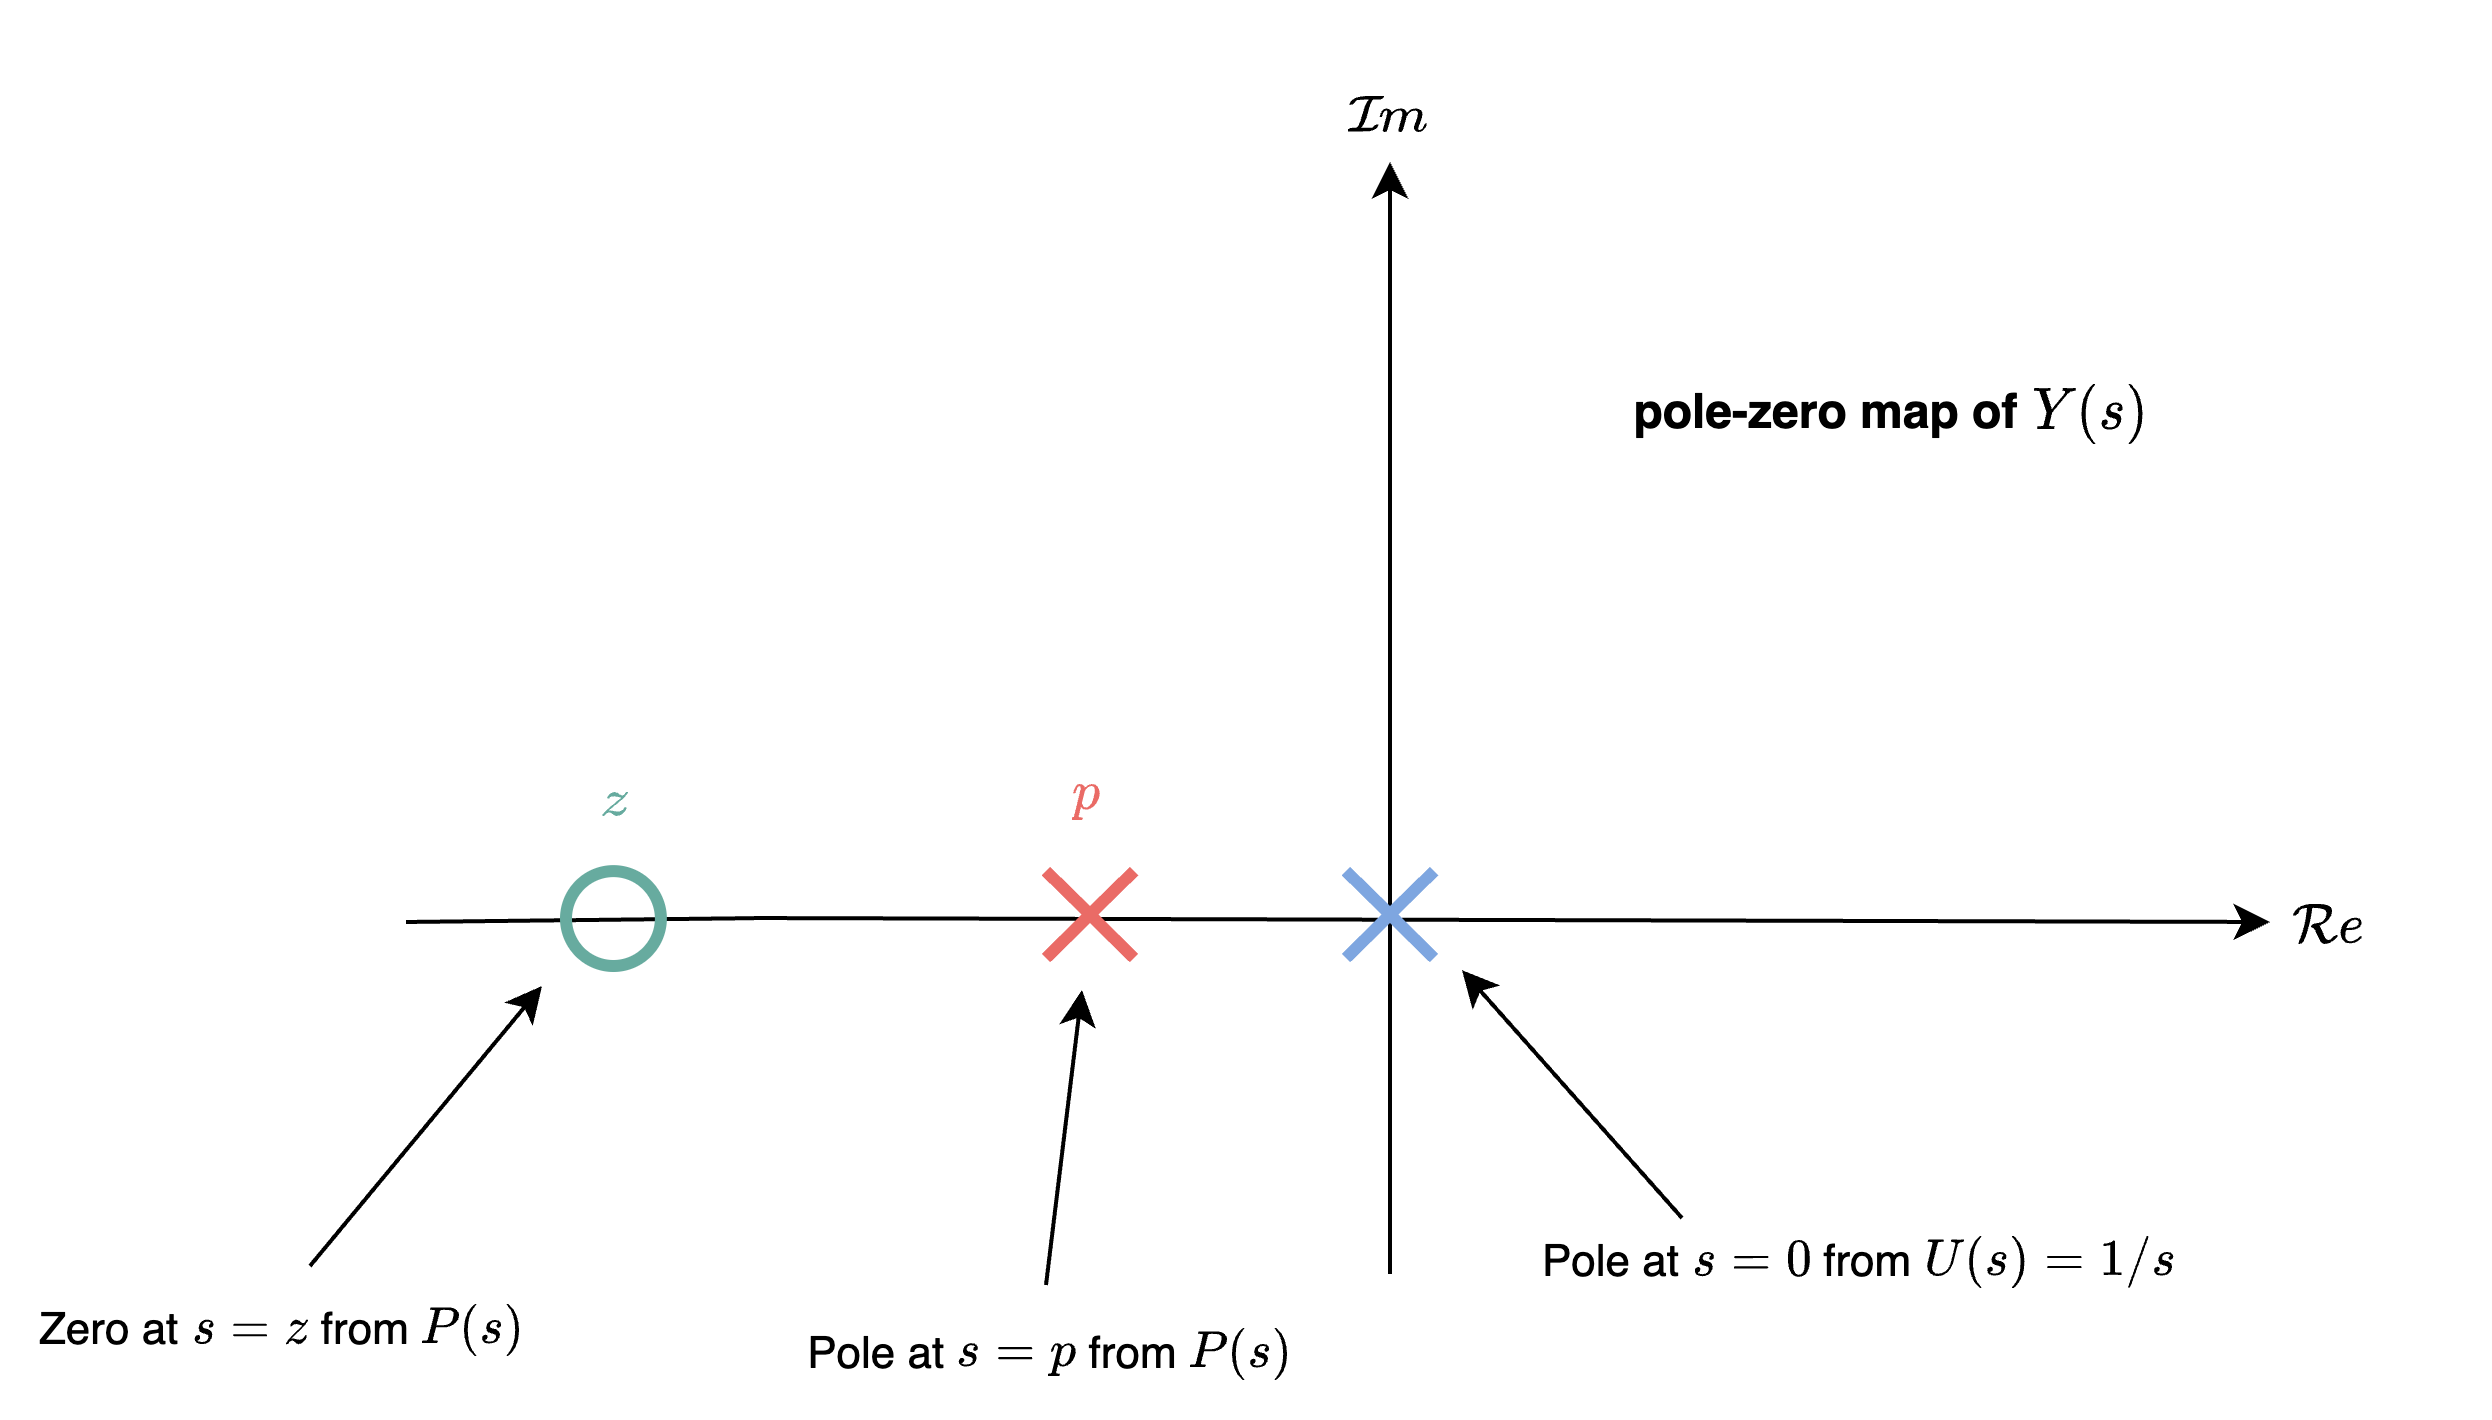

**Figure 6.1:** Pole-zero map of $Y(s)$.

## 6.2 First-order all-pole systems

We now discuss first-order systems without zeros to define a performance specification for such a system. The generalised first-order system without zeros can be described by the transfer function

$P(s)=\frac{K}{s-p}$,

where $\{K,p\}\in \mathbb{R}$. If the input is a unit step, $U(s)=1/s$, the Laplace transform of the step response is

$Y(s)=P(s)U(s)=\frac{K}{s(s-p)}$.

The partial fraction expansion of $Y(s)$ follows as


$$Y(s)=\frac{A}{s}+\frac{B}{s-p}=-\frac{K/p}{s}+\frac{K/p}{s-p}$$


Taking the inverse transform, the step response is given by

$y(t)=y_f(t)+y_n(t)=-\frac{K}{p}+\frac{K}{p}e^{pt}$,

where the structure of:

- $y_f(t)=-\frac{K}{p}$ is the forced response from the pole in $U(s)$ at the origin, and 

- $y_n(t)=\frac{K}{p}e^{pt}$ is the natural response from the pole in $P(s)$ at $s=p$.

The `MATLAB` function `ilaplace` can be used to verify the result of $y(t)$, as shown in the the code block below.

clear 
syms t s K p
P(s) = K/(s-p);
U(s) = 1/s;
Y(s) = P*U(s);
y(t) = ilaplace( Y(s) ) 

$$y(t) = \frac{K\,{\mathrm{e}}^{p\,t}}{p}-\frac{K}{p}$$

The unit step response, $y(t)$, can be generated using the code below, where $K$ and $p$ can be adjusted.

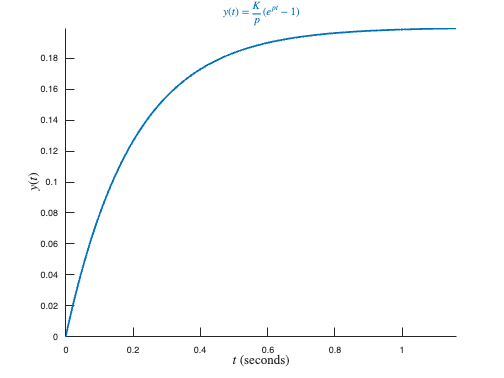

clear
s=tf('s');

K = 1;
p = -5;    
P = K/(s-p);
[y,t] = step(P);

figure,hold on
plot(t,y,lineWidth=2)
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)
title('$y(t)=\frac{K}{p}\left(e^{pt}-1\right)$',Interpreter='latex',FontSize=12,Color='#0072BD')
axis tight

### 6.2.1 Steady-state value

The steady-state value of $y(t)$ is determined by evaluating the function as time tends to infinity.

$\begin{array}{rl}
y(\infty)
&=\lim_{t\rightarrow\infty}y(t),\\
&=\lim_{t\rightarrow\infty}\frac{K}{p}\left(e^{pt}-1\right),\\
&=-\frac{K}{p},\\
&=A_{s}.\\
\end{array}$.

As shown in **Chapter 5**, we can also determine the steady-state value of a bounded response by applying *final-value theorem *in the s-domain. Assuming the output response is bounded (requiring $p<0$), the steady-state (final) value of $y(t)$ is

$\begin{array}{rl}
y(\infty)
&=\lim_{s\rightarrow 0}sY(s),\\
&=\lim_{s\rightarrow 0}\frac{K}{s-p},\\
&=-\frac{K}{p},\\
&=A_{s}.\\
\end{array}$.

The results are equivalent and should match the time-domain simulation generated from the previous code block. 

### 6.2.2 Time constant and exponential frequency

Assuming the response is bounded, we define $T_c=-\frac{1}{p}$ as the **time constant** of the response. This corresponds with the time it takes for the first-order step response to rise to 63% of its final value, which is determined using

$y(T_c)=y(-1/p)=\frac{K}{p}\left(e^{-1}-1\right)\approx -0.63\frac{K}{p} = 0.63A_{s}$.

We can re-parameterise $P(s)$ using the steady-state value, $A_s$, and time constant, $T_c$, as

$P(s)=\frac{K}{s-p}=\frac{-K/p}{-s/p+1}=\frac{A_{s}}{T_cs+1}$.

Using the above parameterisation, the unit step response can be rewritten as

$y(t)=A_s\left(1-e^{-t/T_c}\right)$.

Note that this only applies when the step input has a unit magnitude. In general, if a step input of $U(s)=\frac{\beta}{s}$ is applied, then the output response will be 

$y(t)=\beta A_s\left(1-e^{-t/T_c}\right)$.

clear
s=tf('s');

K = 2;
p = -6;
P = K/(s-p)


P =
 
    2
  -----
  s + 6
 
Continuous-time transfer function.
Model Properties


[y,t] = step(P);

figure,clf,hold on

plot(t,y,lineWidth=2)
line(-1/p*[1 1],[0 -0.63*K/p],Color='red')
line([0 -1/p],-0.63*K/p*[1 1],Color='red')
plot(-1/p,-0.63*K/p,'ro')
text(-1/p,-0.05*K/p,['T_c=',num2str(-1/p,2)])

t=1/p

t = -0.1667


-0.63*K/p

ans = 0.2100


K/p

ans = -0.3333

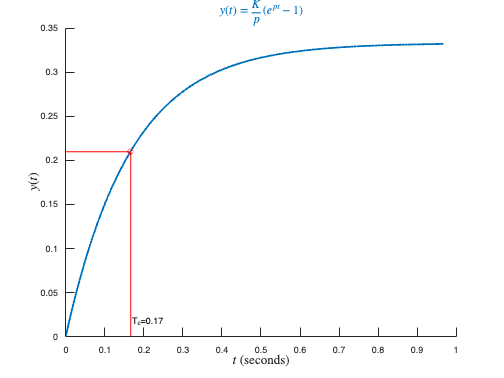


xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)
title('$y(t)=\frac{K}{p}\left(e^{pt}-1\right)$',Interpreter='latex',FontSize=13,Color='#0072BD')

The reciprocal of the time constant has the units (1/seconds), or frequency. Thus, we refer to the parameter $\alpha=-p=1/T_c$ as the **exponential frequency**, which can be used to represent $P(s)$ as

$P(s)=\frac{K}{s-p}=\frac{K}{s+\alpha}=\frac{A_{s}}{s/\alpha+1}$.

It is important to see that all the above representations of $P(s)$ are *equivalent*, but they use different *parameterisations*.

We can determine the initial rate of change of $y(t)$ by determining the time-derivative, $\dot{y}(t)$, and then evaluating it at $t=0$:

$\lim_{t\rightarrow 0}\dot{y}(t) = \lim_{t\rightarrow 0}Ke^{pt} =K$.

Thus, the gain term, $K$, will directly determine how quickly the first-order system initially responds. 

### 6.2.3 Settling time

The ($\pm 2\%$)** settling time **is defined as the time for the response to *reach, and stay within*, $2\%$ of its final value of $y(\infty)=A_s$. Given that we know the response has no overshoot or oscillatory behaviour, we know that once the output response enters the $2\%$ band, it will stay in the band. Letting $y(t)=0.98A_s$, and solving for time, $t$, we find the settling time to be

$T_s\approx\frac{4}{-p}=\frac{4}{\alpha}=4T_c$.

clear 
s=tf('s');

K = 6;
p = -6;
P = K/(s-p)


P =
 
    6
  -----
  s + 6
 
Continuous-time transfer function.
Model Properties


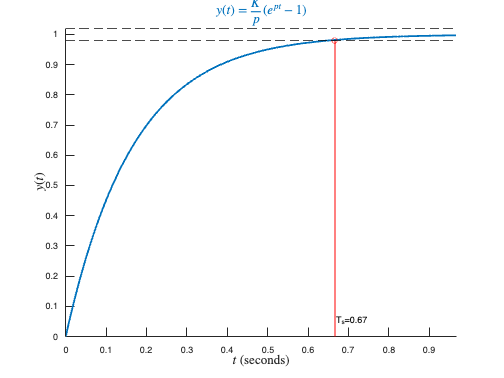

figure,clf,hold on
[y,t] = step(P);
plot(t,y,lineWidth=2)
yline(-1.02*K/p,'k--')
yline(-0.98*K/p,'k--')
line(-4/p*[1 1],[0 -0.98*K/p],Color='red')
plot(-4/p,-0.98*K/p,'ro')
text(-4/p,-0.05*K/p,['T_s=',num2str(-4/p,2)])

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)
title('$y(t)=\frac{K}{p}\left(e^{pt}-1\right)$',Interpreter='latex',FontSize=14,Color='#0072BD')
axis tight

### 6.2.4 First-order transfer functions via testing

Often it is not possible or practical to obtain a system's transfer function analytically. Perhaps the system is closed, and the component parts are not easily identifiable. Since the transfer function is a representation of the system from input to output, the system's step response (if bounded) can lead to a representation even though the inner construction is not known. With a step input, we can measure the time constant and the steady-state value, from which the transfer function can be calculated.

Consider the unit step response of a first-order system

$Y(s)=P(s)U(s)=\frac{K}{s(s-p)}=\frac{A_s}{s(T_cs+1)}$,

where $A_s$ and $T_s$ are unknown. As shown in the figure generated from the code below, we can determine $A_s$ by measuring the steady-state value of $y(t)$. Time constant $T_c$ is estimated by finding the time point, $t=T_c$, at which $y(t)\approx 0.63y(\infty)=0.63A_s$. 

clear
s=tf('s');

K = 2;
p = -6;
P = K/(s-p)


P =
 
    2
  -----
  s + 6
 
Continuous-time transfer function.
Model Properties


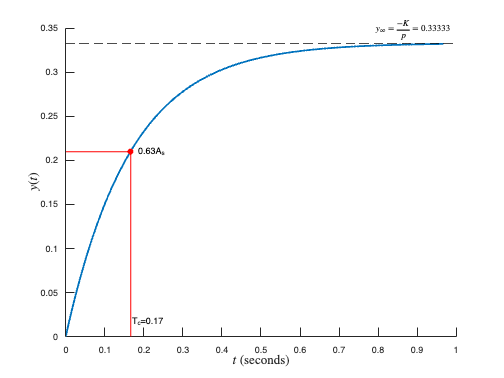


As = -K/p;

figure,clf,hold on
[y,t] = step(P);
plot(t,y,lineWidth=2)
line(-1/p*[1 1],[0 0.63*As],Color='red')
line([0 -1/p],0.63*As*[1 1],Color='red')

text(-1/p,0.05*As,['T_c=',num2str(-1/p,2)])
text(-1/p*1.1,.63*As,'0.63A_s')
plot(-1/p,0.63*As,'ro',MarkerFaceColor='red')

yline(As,'--k',['$y_\infty=\frac{-K}{p}=$',num2str(As)],Interpreter='latex')

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)

%title('$y(t)=\frac{K}{p}\left(e^{pt}-1\right)$',Interpreter='latex',FontSize=15,Color='#0072BD')

We can therefore construct a transfer function model of our first-order system if we can obtain step response data.

## 6.3 Second-order systems

Let us now extend the concepts of poles and zeros and transient response to second-order systems. Compared to the simplicity of a first-order system, a second-order system exhibits a wide range of responses that must be analyzed and classified. The generalised second-order system with no zeros is described as

$P(s)=\frac{K}{s^2+d_1s+d_2}$.

The poles are determined by solving $s^2+d_1s+d_2=0$:

$p_{1,2}=\frac{-d_1\pm \sqrt{d_1^2-4d_2}}{2}$.

We can also express the poles in their complex form as

$p_i=a_i+jb_i$,

where $a_i=\mathcal{R}\{{p_i\}$ and $b_i=\mathcal{I}\{p_i\}$. Depending on the values of $d_1$ an $d_2$, and assuming the poles lie in the OLHP, the two poles will either be 

- strictly negative-real and distinct (unique) — $b_1=b_2=0$, $a_i<0$, $a_1\neq a_2$.

- strictly negative-real and equivalent — $b_1=b_2=0$, $a_i<0$, $a_1= a_2$.

- strictly imaginary complex conjugates — $a_1=a_2=0$, $b_1=-b_2$. 

- complex conjugates with nonzero real and imaginary components — $a_1=a_2\neq 0$, $b_1=-b_2 \neq 0$.

We will classify these four types of systems in the subsequent sections.

### 6.3.1 Overdamped response

A 2nd-order system is **overdamped** when the two system poles, $p_i=a_i+jb_i$, are:

- *negative-real, *$b_1=b_2=0$, $\{a_1,a_2\}<0$, and

- *distinct*: $a_1\neq a_2$,

as shown in the figure below.

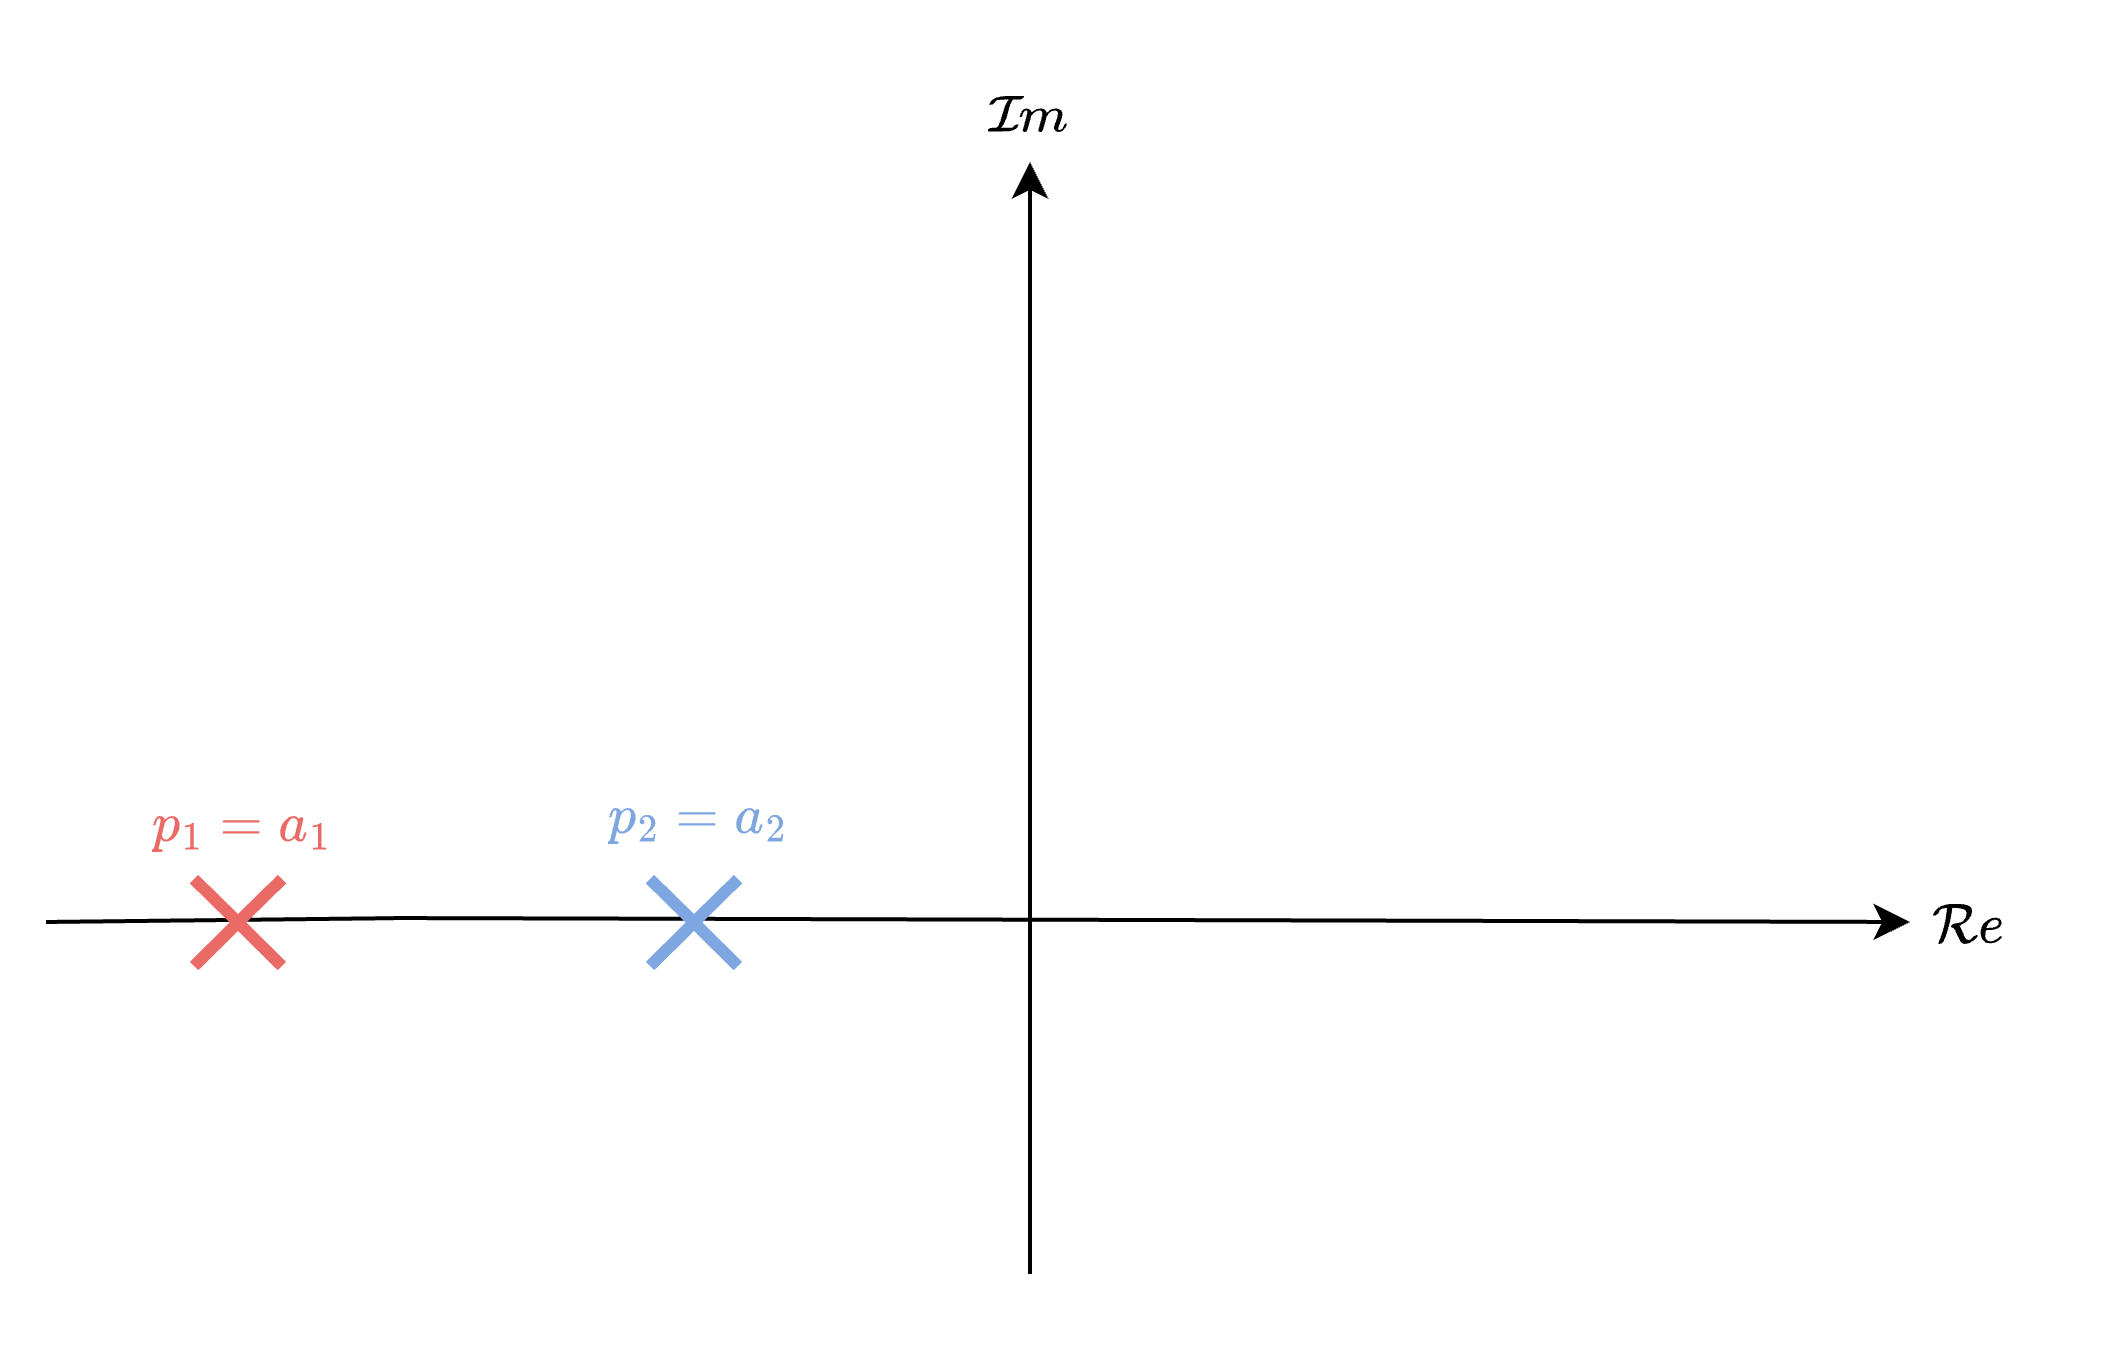

**Figure 6.2:** Pole-zero map of overdamped system with two real OLHP poles.

The *zero-pole-gain* representation is

$P(s)=\frac{K}{(s-p_1)(s-p_2)}=\frac{K}{s^2-(p_1+p_2)s+p_1p_2}$.

The unit step response in the Laplace domain is

$Y(s)=\frac{K}{s(s-p_1)(s-p_2)}=\frac{A}{s}+\frac{B}{s-p_1}+\frac{C}{s-p_2}$,

and using our understanding of partial fraction expansion from **Chapter 5**, the corresponding time response follows as

$\begin{array}{rl}
y(t)
&={A}+Be^{p_1t}+Ce^{p_2t},\\
&=\frac{K}{p_1p_2}+\frac{K}{p_1(p_1-p_2)}e^{p_1t}-\frac{K}{p_2(p_1-p_2)}e^{p_2t},\\
&=\frac{K}{a_1a_2}+\frac{K}{a_1(a_1-a_2)}e^{a_1t}-\frac{K}{a_2(a_1-a_2)}e^{a_2t}.\\
\end{array}$.

The code block below is used to confirm this result.

clear 
syms t s K p1 p2
P(s) = K/(s-p1)/(s-p2);
U(s) = 1/s;
Y(s) = P*U(s);
y(t) = ilaplace( Y(s) ) 

$$y(t) = \frac{K}{p_{1}\,p_{2}}+\frac{K\,{\mathrm{e}}^{p_{1}\,t}}{p_{1}\,\left(p_{1}-p_{2}\right)}-\frac{K\,{\mathrm{e}}^{p_{2}\,t}}{p_{2}\,\left(p_{1}-p_{2}\right)}$$

Based on the equation for $y(t)$, the steady-state value can be determined as 


$$\begin{array}{rl}
y(\infty)
&=\lim_{t\rightarrow \infty}y(t),\\
&=\frac{K}{a_1a_2},\\
&=A_{s}.\\
\end{array}$$


The unit step response has a pole at the origin that comes from the unit step input and two real poles that come from the system. The input pole at the origin generates the constant forced response; each of the two system poles on the real axis generates an exponential natural response whose exponential frequency is equal to the pole location in the $s$-plane. The unit step response and pole-zero map of $P(s)$ is generated using the code below, where $K$, $p_1=a_1$, and $p_2=a_2$ can be adjusted.

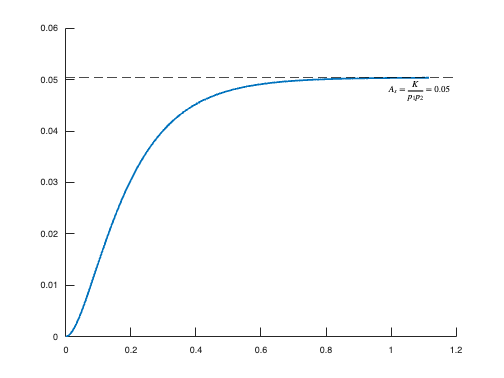

clear

K = 6;
p1 = -17;%p1=a1
p2 = -7;%p2=a2

s = tf('s');
P = K/(s-p1)/(s-p2);
[y,t] = step(P);

%y(t)
figure,clf,hold on
plot(t,y,lineWidth=2)
yline(K/p1/p2,'--k',['$A_s=\frac{K}{p_1p_2}=$',num2str(K/p1/p2,2)],Interpreter='latex',LabelVerticalAlignment='bottom')

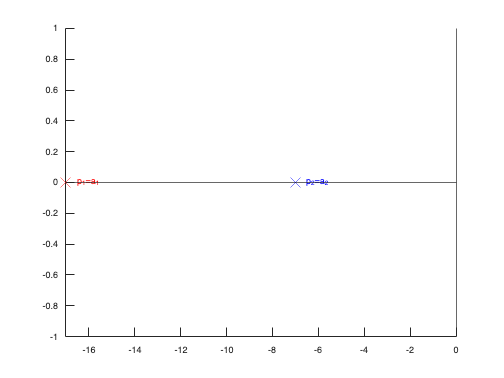

%s-plane
figure,clf,hold on
plot(real(p1),imag(p1),'rx',MarkerSize=15)
text(real(p1),imag(p1),'  p_1=a_1',Color='r')
plot(real(p2),imag(p2),'bx',MarkerSize=15)
text(real(p2),imag(p2),'  p_2=a_2',Color='b')
yline(0),xline(0)
axis tight

The pole locations inform us of the shape of response — where all poles on the real axis (no imaginary components) implies an overdamped response. The slowest pole (the one closest to the origin) will dominate the response and will predominantly affect the settling time of the response. This is because the faster pole has a smaller time constant and its exponential term will decay quicker.

### 6.3.2 Critically-damped response

A 2nd-order system's output response is **critically-damped** when the two system poles, $p_i=a_i+jb_i$, are: 

- *negative-real, *$b_1=b_2=0$, $\{a_1,a_2\}<0$, and

- *equivalent*: $p_1=p_2$ (equivalently, $a_1=a_2$),

as shown in the figure below.

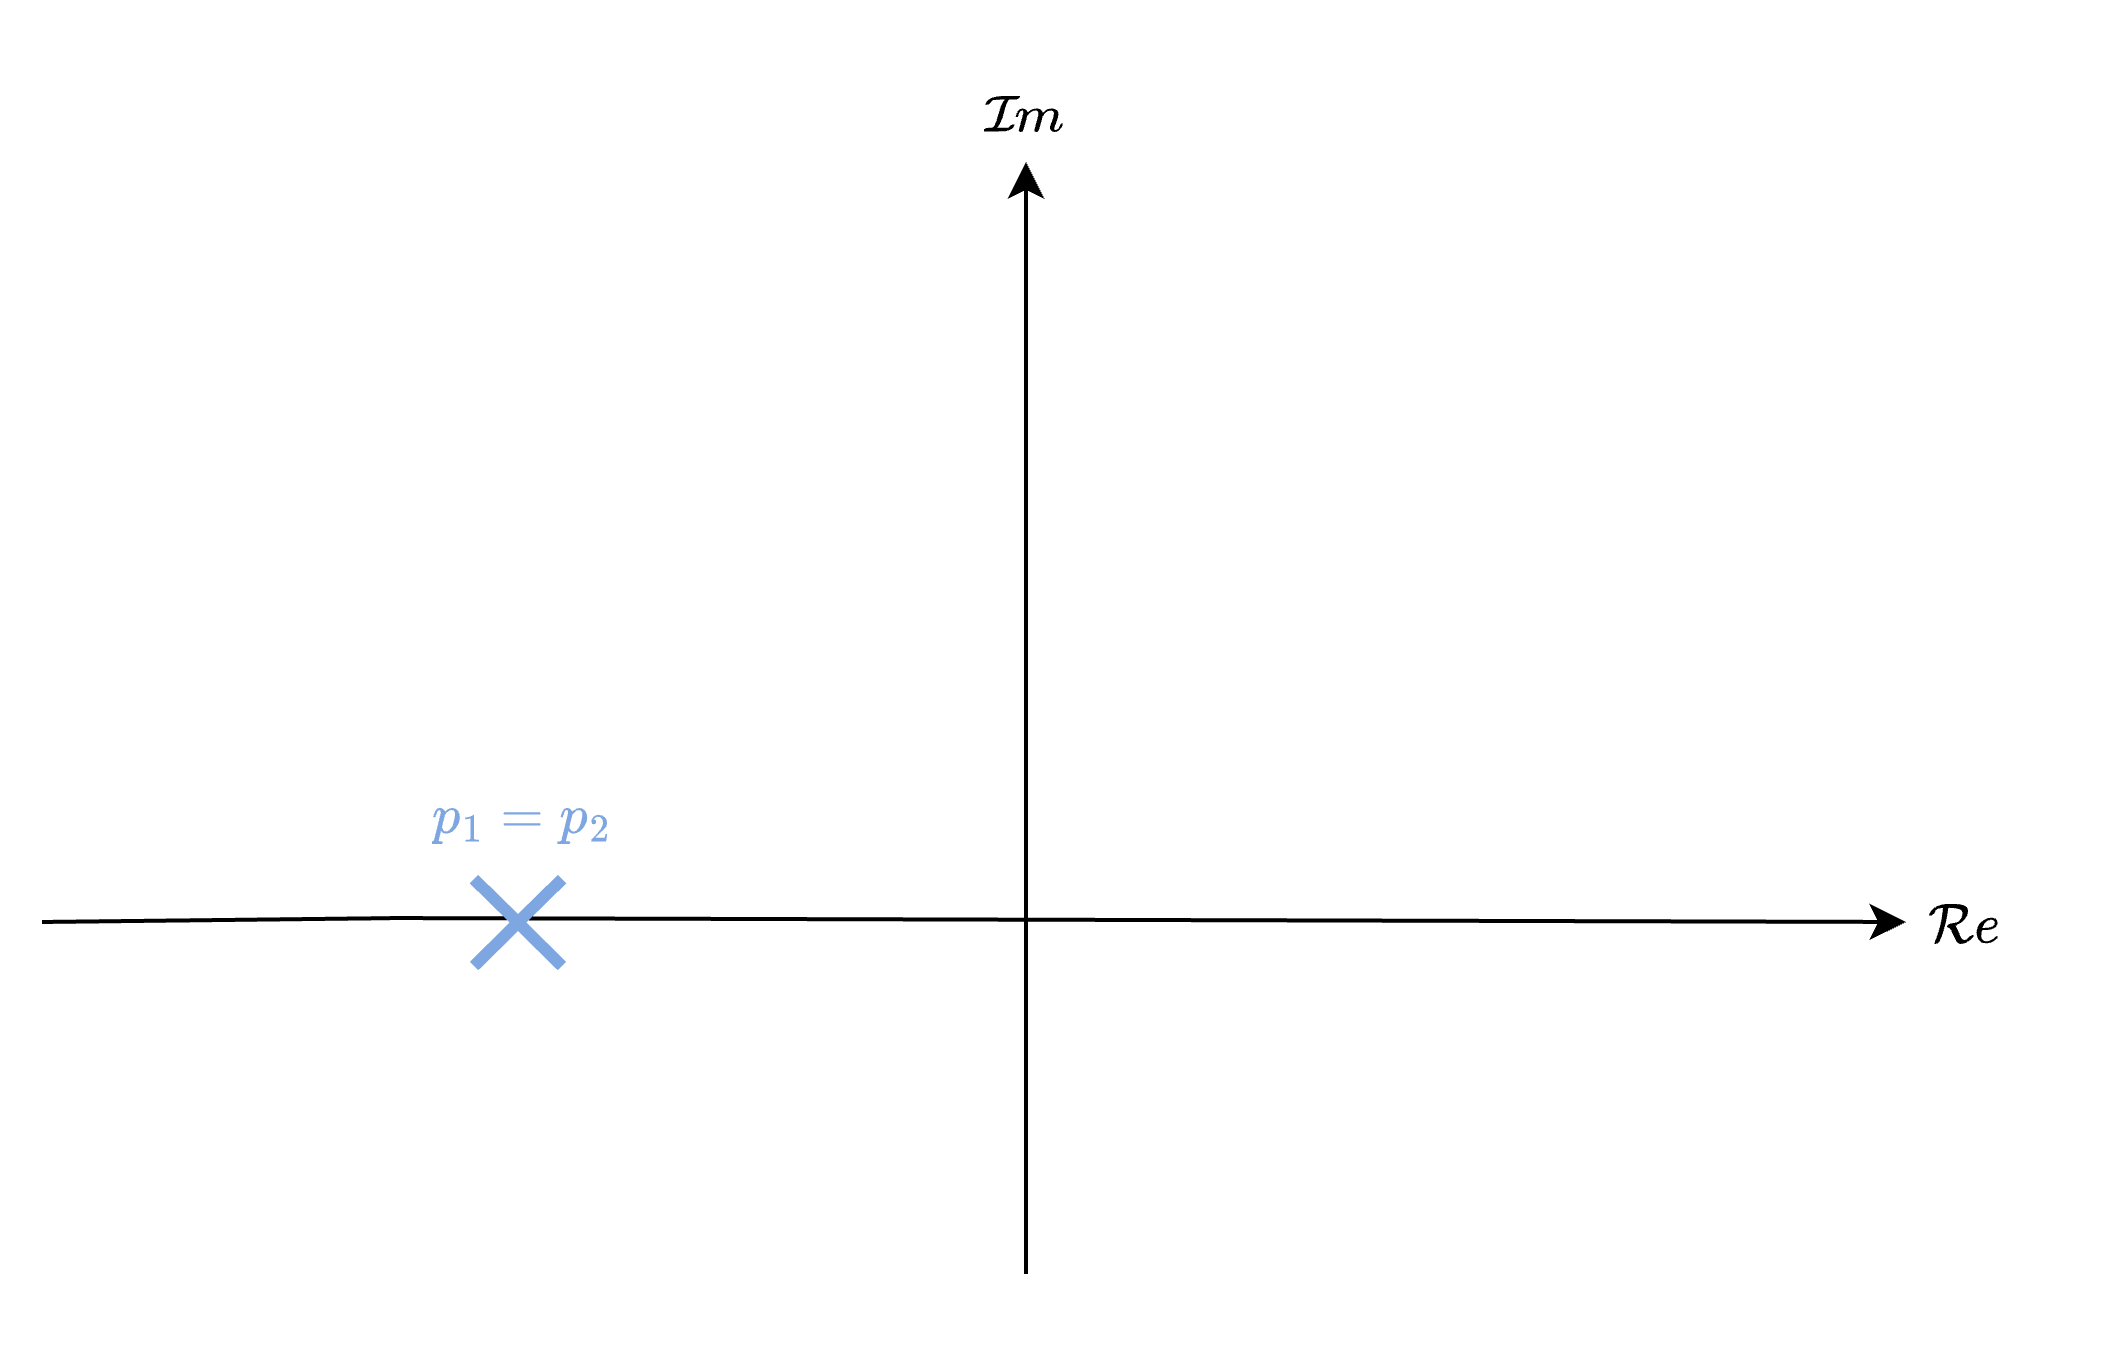

**Figure 6.3:** Pole-zero map of critically-damped system.

The *zero-pole-gain* representation is

$P(s)=\frac{K}{(s-p_1)^2}$.

The unit step response in the Laplace domain is

$Y(s)=\frac{K}{s(s-p_1)^2}=\frac{A}{s}+\frac{B}{(s-p_1)^2}+\frac{C}{s-p_1}$,

and the corresponding time-domain response is

$\begin{array}{rl}
y(t)
&=A+Bte^{pt}+Ce^{p_1t},\\
&=\frac{K}{p_1^2}+\frac{K}{p_1}te^{p_1t}-\frac{K}{p_1^2}e^{p_1t},\\
\end{array}$.

The code block below is used to confirm this result.

clear 
syms t s K p_1
P(s) = K/(s-p_1)^2;
U(s) = 1/s;
Y(s) = P*U(s);
y(t) = ilaplace( Y(s) ) 

$$y(t) = \frac{K}{{p_{1}}^{2}}-\frac{K\,{\mathrm{e}}^{p_{1}\,t}}{{p_{1}}^{2}}+\frac{K\,t\,{\mathrm{e}}^{p_{1}\,t}}{p_{1}}$$

Based on the equation for $y(t)$, the steady-state value can be determined as 


$$\begin{array}{rl}
y(\infty)
&=\lim_{t\rightarrow \infty}y(t),\\
&=\frac{K}{p_1^2},\\
&=A_{s}.\\
\end{array}$$


The step response is made up a step from the forced response of the input, an exponentially-decaying ramp signal, and an exponentially-decaying constant. Note the mathematical difference between the step response of a critically-damped and underdamped system. 

The unit step response and pole-zero map of $P(s)$ is generated using the code below, where $K$ and $p$ can be adjusted.

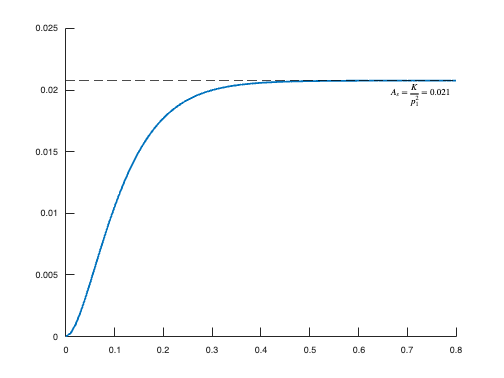

clear

K = 6;
p1 = -17;

s = tf('s');
P = K/(s-p1)^2;
[y,t] = step(P);

%y(t)
figure,clf,hold on
plot(t,y,lineWidth=2)
yline(K/p1^2,'--k',['$A_s=\frac{K}{p_1^2}=$',num2str(K/p1^2,2)],Interpreter='latex',LabelVerticalAlignment='bottom')

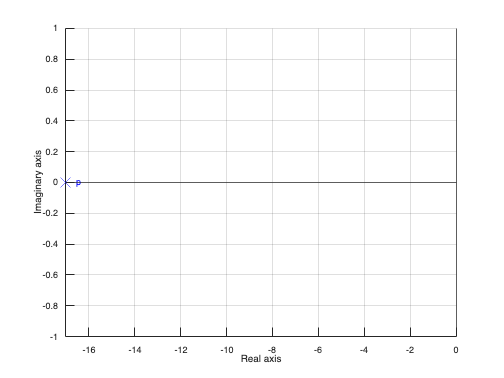

%s-plane
figure,clf,hold on
plot(real(p1),imag(p1),'bx',MarkerSize=15)
text(real(p1),imag(p1),'    p',Color='b')
yline(0),xline(0)
xlabel('Real axis'), ylabel('Imaginary axis')
grid on, axis tight

### 6.3.3 Underdamped response

A 2nd-order system's output response is **underdamped** when the system has *complex-conjugate *poles — poles with both real and imaginary components*. *That is, two poles with equivalent negative-real components, and imaginary components that are equal in magnitude, but opposite in sign, namely

 $p_{1,2}=a\pm jb$.

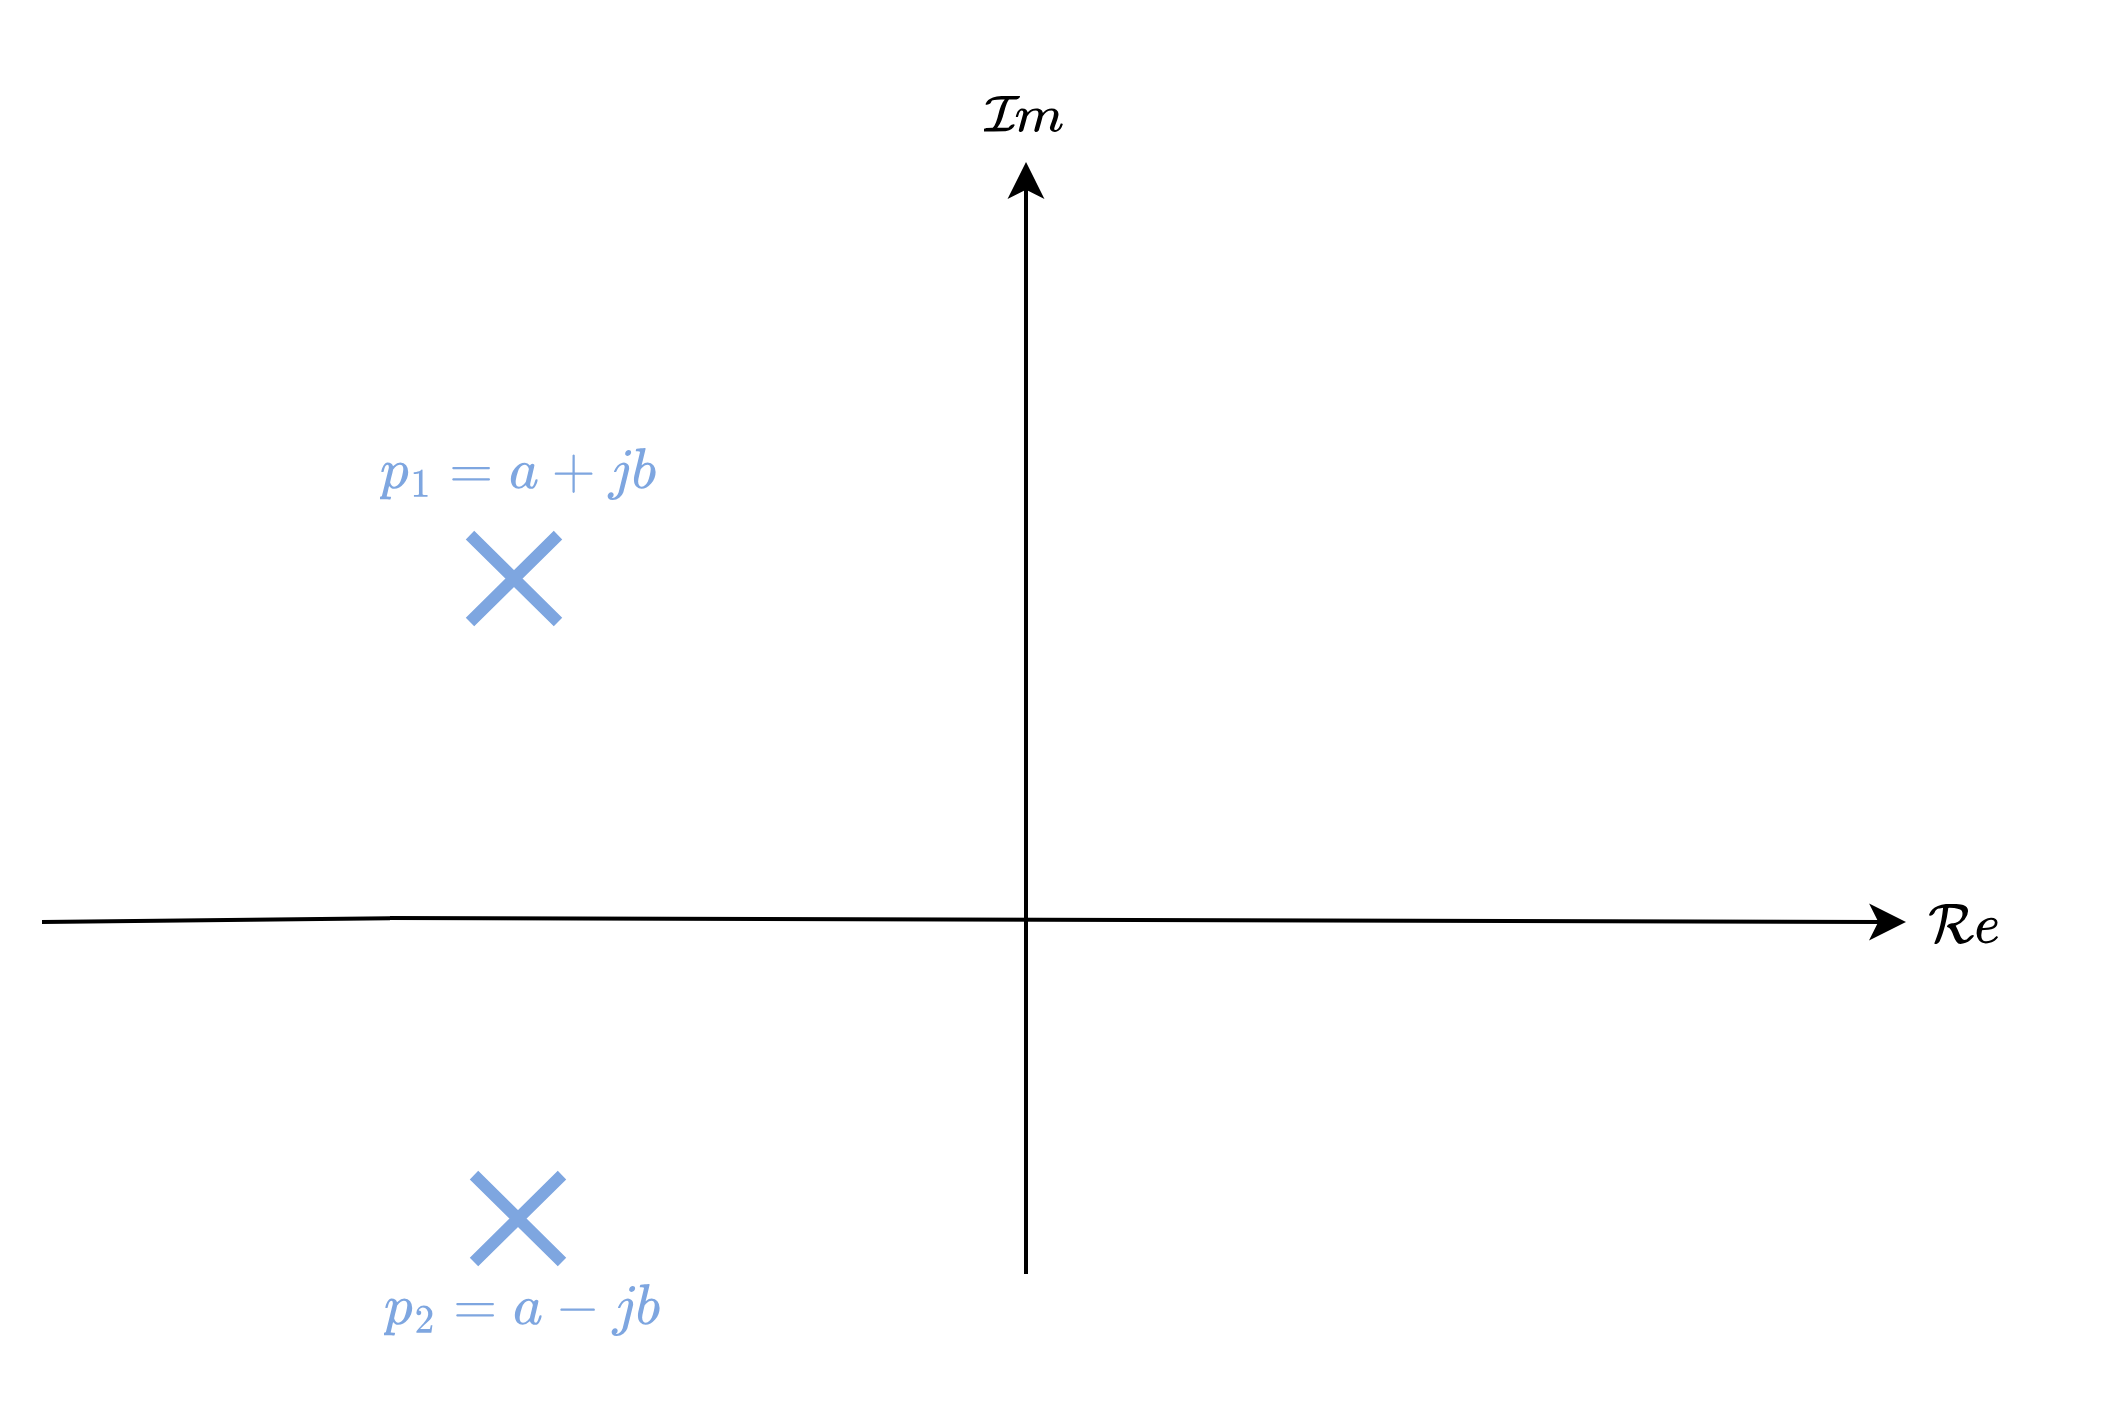

**Figure 6.4:** Pole-zero map of under-damped system.

The *zero-pole-gain *representation is given as


$$\begin{array}{rl}
P(s)
&=\frac{K}{(s-a+jb)(s-a-jb)},\\
&=\frac{K}{s^2-2a s+(b^2+a^2)}.
\end{array}$$


The unit step response in the Laplace domain is given by


$$\begin{array}{rl}
Y(s)
&=\frac{K}{s(s^2-2a s+(b^2+a^2))},\\
&=\frac{A}{s}+\frac{B(s-a)+Cb}{(s-a)^2+b^2},\\
&=\frac{A}{s}+\frac{B(s-a)}{(s-a)^2+b^2}+\frac{Cb}{(s-a)^2+b^2},
\end{array}
$$


and the corresponding time-domain response is


$$\begin{array}{ll} 
y(t) 
&= A+e^{a t}\left[B\cos(a t)+C\sin(b t)\right], \\
&=A+De^{a t}\cos(b t-\phi),
\end{array}$$


where $D=\sqrt{B^2+C^2}$, and $\phi=-\tan^{-1}\frac{C}{B}$.

Note that we used the following transforms and identities:

- 
$$\sin(\omega t) = \mathcal{L}^{-1}\{ \frac{\omega}{s^2+\omega^2}\}$$


- 
$$\cos(\omega t) =\mathcal{L}^{-1}\{ \frac{s}{s^2+\omega^2}\}$$


- 
$$e^{at} f(t) = \mathcal{L}^{-1}\{ F(s-a)\}$$


Based on the structure of $Y(s)$, the steady-state value can be determined as 


$$\begin{array}{rl}
y(\infty)
&=\lim_{s\rightarrow 0}sY(s),\\
&=\lim_{s\rightarrow 0}\frac{K}{s^2-2a s+(b^2+a^2)},\\
&=\frac{K}{a^2+b^2},\\
&=A_{s}.\\
\end{array}$$


The unit step response is made up of the forced response, $A=\frac{K}{a^2+b^2}$, and a damped co-sinusoid, $De^{a t}\cos(b t-\phi)$, with an exponential envelope whose time constant is equal to the reciprocal of the pole's real part, $-1/a$. The step response and pole-zero map of $P(s)$ is generated using the code below.

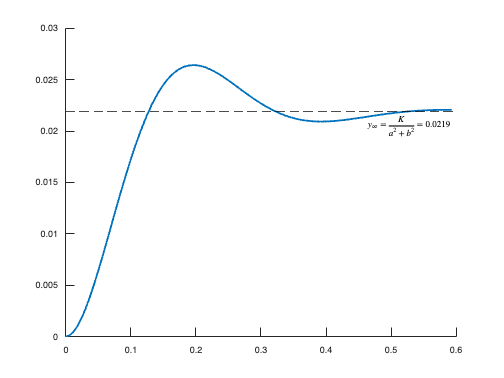

clear

K = 7;
a = -8;
b = 16;

s = tf('s');
p1 = a+1i*b;
p2 = a-1i*b;
P = K/(s-p1)/(s-p2);
[y,t] = step(P);

%y(t)
figure,clf,hold on
plot(t,y,lineWidth=2)
yline(K/(a^2+b^2),'--k',['$y_\infty=\frac{K}{a^2+b^2}=$',num2str(K/(a^2+b^2),3)],Interpreter='latex',LabelVerticalAlignment='bottom')

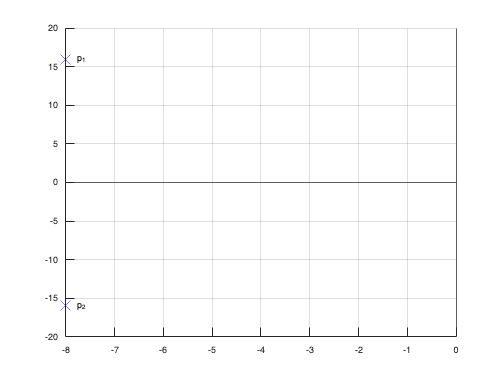

%s-plane
figure,clf,hold on
plot(real(p1),imag(p1),'bx',MarkerSize=15)
text(real(p1),imag(p1),'  p_1')
plot(real(p2),imag(p2),'bx',MarkerSize=15)
text(real(p2),imag(p2),'  p_2')
yline(0),xline(0)
grid on

The frequency of the cosine, known as the damped frequency of oscillation, is equal to the imaginary part of the poles, $b$. We also observe that the real part of the complex conjugate pole pair, $a$, contributes the exponential decay, which has the effect of dampening the oscillatory response as time progresses. We can visualise this by overlaying the step response with the exponential decay functions $\frac{K}{b^2}(1\pm e^{at})$, as shown using the code below.

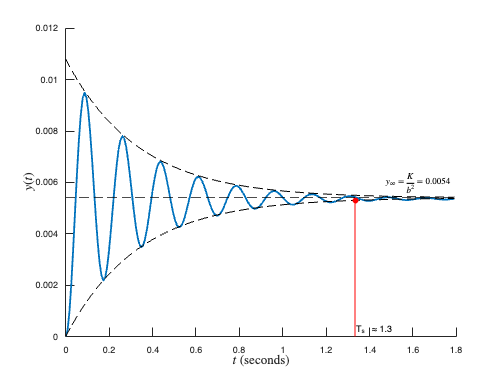

clear

K = 7;
a = -3;
b = 36;

s = tf('s');
p1 = a+1i*b;
p2 = a-1i*b;
P = K/(s-p1)/(s-p2);
[y,t] = step(P);

ea = K/b^2*(1+exp(a*t));
eb = K/b^2*(1-exp(a*t));

%y(t)
figure,clf,hold on
plot(t,y,lineWidth=2)
plot(t,ea,'k--')
plot(t,eb,'k--')
yline(K/b^2,'--k',['$y_\infty=\frac{K}{b^2}=$',num2str(K/b^2,3)],Interpreter='latex',LabelVerticalAlignment='top')

line(-4/a*[1 1],[0 0.98*K/b^2],Color='red')
plot(-4/a,0.98*K/b^2,'ro',MarkerFaceColor='r')
text(-4/a,0.05*K/b^2,['T_s \approx',num2str(-4/a,2)])
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)

As a result, the $2\%$ settling time of an under-damped 2nd-order system is approximated as

$T_s \approx\frac{-4}{a}$,

which is equivalent to the settling time of $\frac{K}{b^2}(1\pm e^{at})$. Note that the result above is a conservative approximation, as the exponential bands are only equal to the output response when the cosine function is at one of its peaks.

If we can estimate $T_s$ from a unit step response, we can then infer that the real part of our complex pole pair is $a=\frac{-4}{T_s}$. The frequency of oscillation value, $b$, can also be determined from the response by measuring the sinusoidal peak-to-peak time, $\Delta T$. The damped frequency of oscillation follows as

$b=\frac{2\pi}{\Delta T}$.

### 6.3.4 Undamped response

A 2nd-order system's output response is **undamped** when the system has *purely imaginary conjugate poles. *That is, two poles that sit on the imaginary axis of the s-plane and are equidistant from the origin, namely

 $p_{1,2}=\pm jb$.

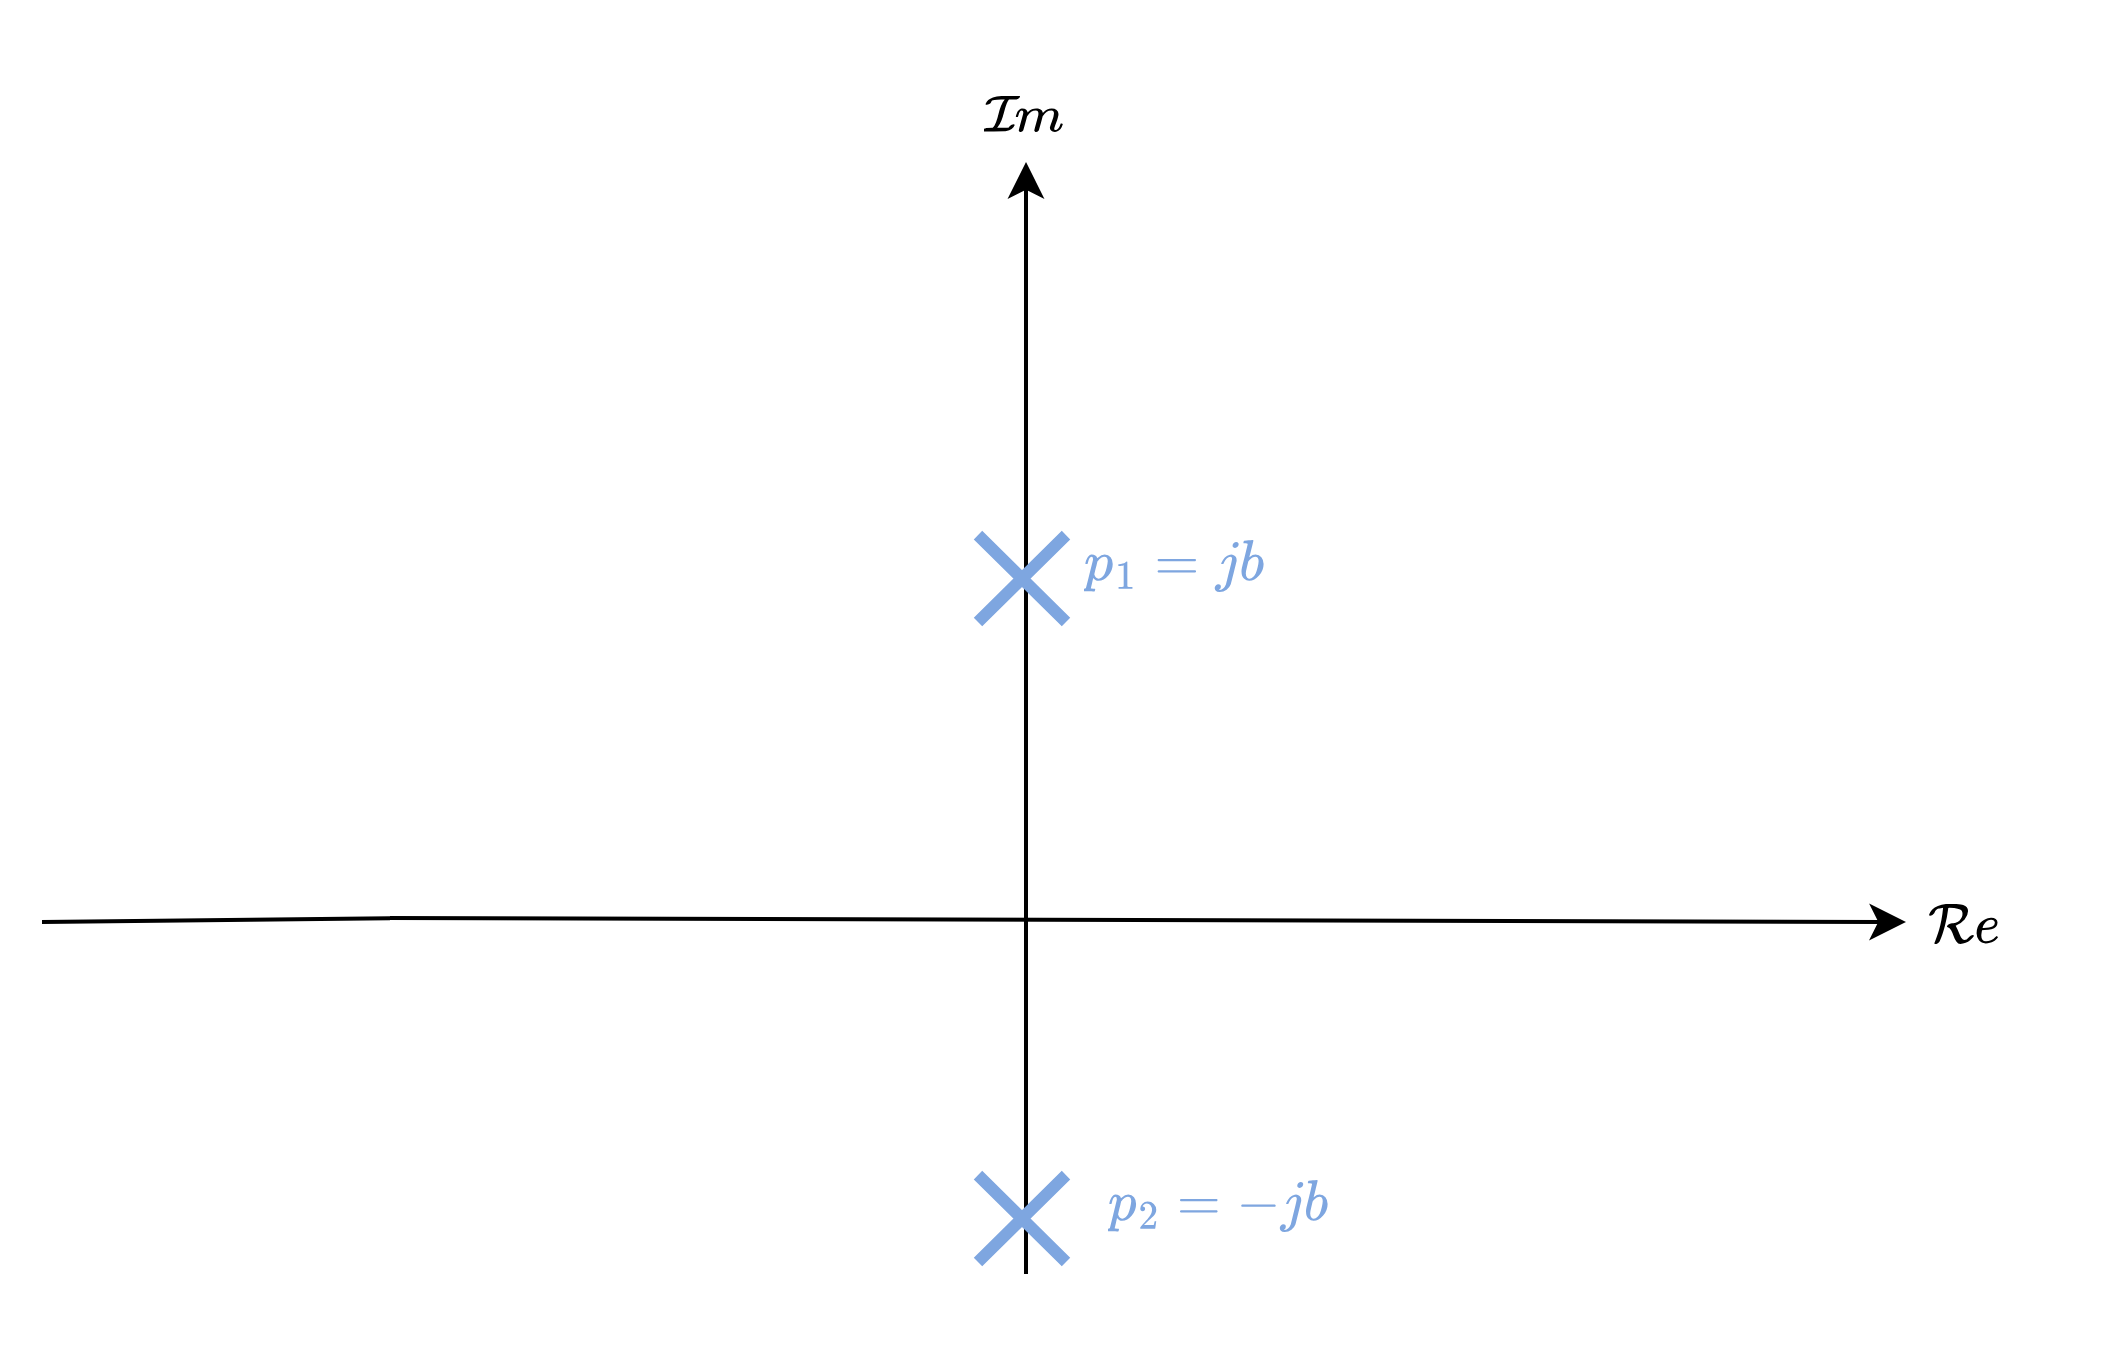

**Figure 6.5:** Pole-zero map of undamped system.

The corresponding transfer function follows as

$P(s)=\frac{K}{(s+jb)(s-jb)}=\frac{K}{s^2+b^2}$.

The unit step response in the Laplace domain is

$Y(s)=\frac{K}{s(s^2+b^2)}=\frac{A}{s}+\frac{Bs}{s^2+b^2}$,

and the corresponding time-domain response is

$\begin{array}{ll} 
y(t) 
&= A+B\cos(b t)
\end{array}$.

Note that the absence of a real part in the complex conjugate pole pair corresponds to an exponential that does not decay. Mathematically, the exponential is $e^{0t}=1$. As a result, the unit step response is made up of the forced response, $A$, and an undamped co-sinusoid, $B\cos(bt)$, with a frequency of oscillation equal to the imaginary part of the poles, $b$. 

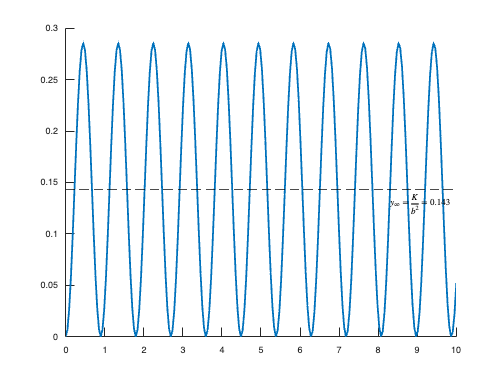

clear

K = 7;
b = 7;

s = tf('s');
P = K/(s^2+b^2);
[y,t] = step(P,10);

%y(t)
figure,clf,hold on
plot(t,y,LineWidth=2)
yline(K/b^2,'--k',['$y_\infty=\frac{K}{b^2}=$',num2str(K/b^2,3)],Interpreter='latex',LabelVerticalAlignment='bottom')

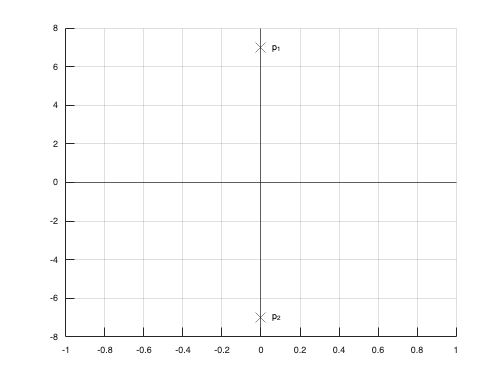

%s-plane
p1 = 1i*b;
p2 = -1i*b;
figure,clf,hold on
plot(real(p1),imag(p1),'bx',MarkerSize=15)
text(real(p1),imag(p1),'  p_1')
plot(real(p2),imag(p2),'bx',MarkerSize=15)
text(real(p2),imag(p2),'  p_2')
yline(0),xline(0)
grid on

## 6.4 General second-order systems

In this section, we define two physically meaningful specifications for second-order systems. These quantities can be used to describe the characteristics of the second-order transient response just as time constants describe the first-order system response. The two quantities are called *natural frequency* and *damping ratio*. 

### 6.4.1 Natural frequency and damping ratio

The **natural frequency** of a second-order system is the frequency of oscillation of the system without damping. We define this variable as $\omega_n$.

We define the **damping ratio** to be the ratio of the exponential frequency (magnitude of the pole's real component) and natural frequency

$\zeta=\frac{|a|}{\omega_n}$.

### 6.4.2 Reparameterising the system 

Revisiting our original parameterisation of our second-order $P(s)$:

$P(s)=\frac{Kd_2}{s^2+d_1s+d_2}$,

where $K$ represents the steady-state value of the unit step response $Y(s)=P(s)\frac{1}{s}$, namely

$y(t)=\lim_{s\rightarrow 0}sY(s)=\lim_{s\rightarrow 0}P(s)=K$.

We would like to reparameterise our system in terms of $\zeta$ and $\omega_n$. When the system is undamped ($d_1=0$), $P(s)$ takes the form of

$P(s)=\frac{Kd_2}{s^2+d_2}$,

and the resulting pole locations are 

$p_{1,2}=\pm j\sqrt{d_2}$. 

Based on our definition of the natural frequency, that is, the frequency of oscillation in the absence of damping, we can determine that

$\omega_n=\sqrt{d_2}$,

which implies that 

$d_2 = \omega_n^2$. 

Now to determine $a$: Given that the poles of $P(s)$, in general, are defined as

$p_{1,2}=\frac{-d_1\pm \sqrt{d_1^2-4d_2}}{2}$,

if the system is underdamped (implying that the poles are complex conjugates), the real component of the poles are 

$\mathcal{R}\{p_1\}=a=\frac{-d_1}{2}$.

Given that the exponential frequency is defined as $|a|$, the damping ratio can be determined using

$\zeta=\frac{|a|}{\omega_n}=\frac{|d_1/2|}{\omega_n}$,

from which we can determine

$d_1=2\zeta\omega_n$,

where $\{\zeta,\omega_n\}>0$.

Using the above equations, we can reparameterise our second-order system as

$P(s)=\frac{K\omega_n^2}{s^2+2\zeta\omega_n s+\omega_n^2}$.

The poles follow as:

$p_{1,2}=-\zeta\omega_n\pm \omega_n\sqrt{\zeta^2-1}$.

Note that this result generalises to any of the four second-order cases.

### 6.4.3 Summary of responses

Based on the equation for the plant poles above, we can therefore classify the type of system based on the value of the damping ratio, as shown in the table below.

**Table 6.1:** Summary of second-order responses.


$$\left.
\begin{array}{ccc}
\textbf{System type} & \textbf{Damping ratio} & \textbf{Poles} 
\\
\text{Undamped} \quad& \zeta=0 & p_{1,2}=\pm j\omega_n
\\
\text{Underdamped} \quad& 0<\zeta<1 & p_{1,2}=-\zeta\omega_n\pm j\omega_n\sqrt{1-\zeta^2}
\\
\text{Critically-damped} \quad& \zeta=1 & p_{1,2}=-\zeta\omega_n
\\
\text{Overdamped} \quad& \zeta>1 & p_{1,2}=-\zeta\omega_n\pm \omega_n\sqrt{\zeta^2-1}
\end{array}
\right.
$$


Unit step responses of the four types of 2nd-order systems are summarised using the code block below.

clear

s = tf('s');
wn = 1.8;
ZETA = [0 0.5 1 1.5];

figure(1),clf,hold on
for i=1:length(ZETA)

    zeta = ZETA(i);
    P = wn^2/(s^2+2*zeta*wn*s+wn^2)
    [y,t] = step(P,10);
    plot(t,y,lineWidth=2)
end


P =
 
     3.24
  ----------
  s^2 + 3.24
 
Continuous-time transfer function.
Model Properties

P =
 
         3.24
  ------------------
  s^2 + 1.8 s + 3.24
 
Continuous-time transfer function.


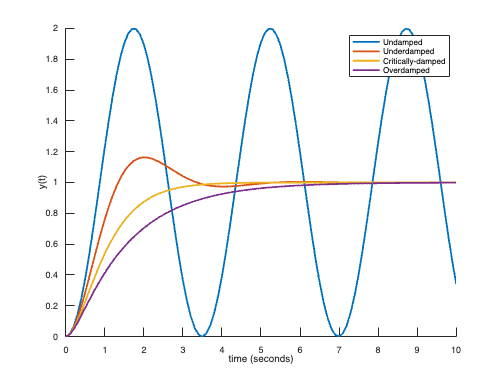

xlabel('time (seconds)'),ylabel('y(t)')
legend('Undamped', 'Underdamped', 'Critically-damped', 'Overdamped')

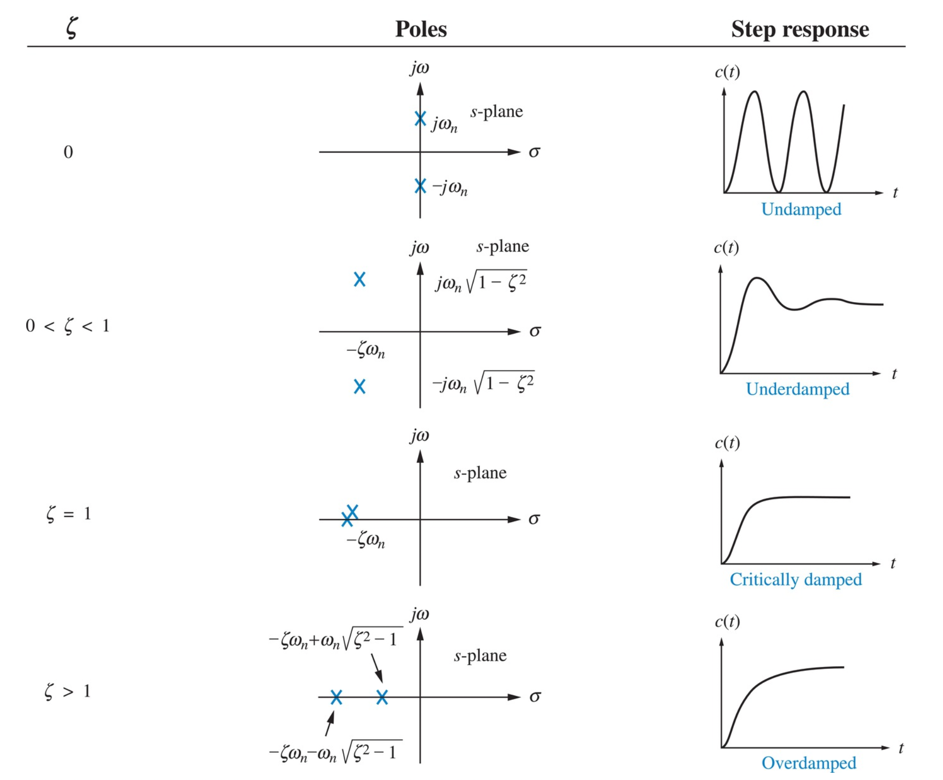

**Figure 6.6:** Summary or relationship between pole locations and step responses for second-order systems.

## 6.5 Underdamped second-order systems

The underdamped second-order system (implying $0<\zeta<1$), a common model for physical problems, displays unique behavior that must be itemised; a detailed description of the underdamped response is necessary for both analysis and design. Understanding this type of response will become very important when dealing with user specifications and desired performance, as often one can represent the performance requirements based on the step response of an underdamped second-order system.

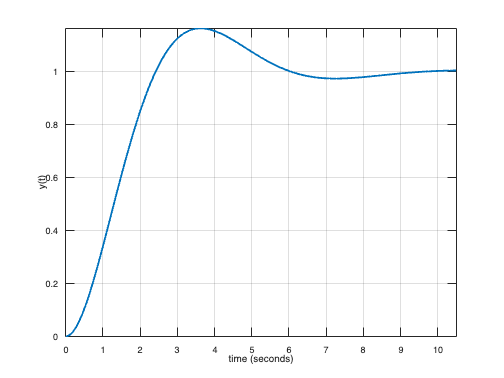

clear
s = tf('s');

wn = 1; %natural frequency
zeta = 0.5; %damping ratio

P = wn^2/(s^2+2*zeta*wn*s+wn^2);
[y,t] = step(P);

figure
plot(t,y,lineWidth=2)
xlabel('time (seconds)'),ylabel('y(t)')
grid on, axis tight

### 6.5.1 Determining the analytical step response

Using the damping ratio, $\zeta$, and natural frequency, $\omega_n$, a second-order system with unit gain ($K=1$) is described as

$P(s)=\frac{\omega_n^2}{s^2+2\zeta\omega_n s+\omega_n^2}$.

 The unit step response in the Laplace domain is

$Y(s)=\frac{\omega_n^2}{s(s^2+2\zeta\omega_n s+\omega_n^2)}=\frac{A}{s}+\frac{Bs+C}{s^2+2\zeta\omega_n s+\omega_n^2}$,

where $0<\zeta<1$ for underdamped systems. Using partial fraction expansion, 

$Y(s)=\frac{1}{s}-\frac{(s+\zeta\omega_n)+\frac{\zeta}{\sqrt{1-\zeta^2}}\omega_n\sqrt{1-\zeta^2}}{(s+\zeta\omega_n)^2+\omega_n^2(1-\zeta^2)}$.

Taking the inverse Laplace transform


$$\begin{array}{ll} 
y(t) &=1-e^{-\zeta\omega_n t}\left[ \cos \left(\omega_n \sqrt{1-\zeta^2}t\right)+\frac{\zeta}{\sqrt{1-\zeta^2}}\sin \left(\omega_n\sqrt{1-\zeta^2}t \right)\right] \\
&= 1-\frac{1}{\sqrt{1-\zeta^2}}e^{-\zeta\omega_nt}\cos\left(\omega_n\sqrt{1-\zeta^2}t-\phi\right)
\end{array}
$$


where $\phi=\tan^{-1}\frac{\zeta}{\sqrt{1-\zeta^2}}$.

Note that we used the following transforms and identities:

- 
$$\sin(\omega t) = \mathcal{L}^{-1}\{ \frac{\omega}{s^2+\omega^2}\}$$


- 
$$\cos(\omega t) =\mathcal{L}^{-1}\{ \frac{s}{s^2+\omega^2}\}$$


- 
$$e^{at} f(t) = \mathcal{L}^{-1}\{ F(s-a)\}$$


Based on the equation for $y(t)$, we can deduce that increasing $\zeta$ reduces the oscillations and overshoot, based on its effect of reducing the amplitude of the co-sinusoid (its effective upper and lower bounds). The natural frequency, $\omega_n$, affects the frequency of oscillation and rate of exponential decay, but it does not alter the fundamental profile of the response.

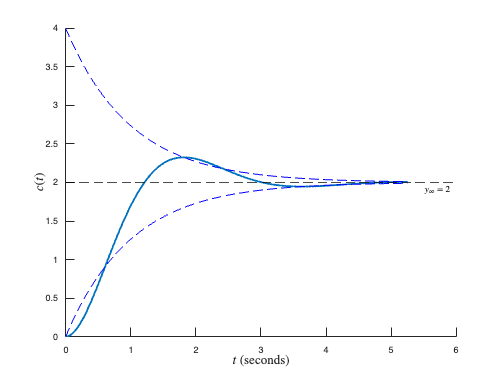

clear
s = tf('s');

K = 2;
zeta = 0.5;
wn = 2;

P = K*wn^2/(s^2+2*zeta*wn*s+wn^2);
[y,t] = step(P);

ea = K*(1+exp(-zeta*wn*t));
eb = K*(1-exp(-zeta*wn*t));

%y(t)
figure,clf,hold on
plot(t,y,LineWidth=2)
plot(t,ea,'b--')
plot(t,eb,'b--')
yline(K,'--k',['$y_\infty=$',num2str(K,2)],Interpreter='latex',LabelVerticalAlignment='bottom')

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$c(t)$',Interpreter='latex',FontSize=15)

### 6.5.2 Performance metrics

The peak time and settling time of a step response yield information about the *speed of the transient response*. This information can help a designer determine whether the speed and the nature of the response degrades the performance of the system. For example, the speed of an entire computer system depends on the time it takes for a hard drive head to reach steady state and read data; passenger comfort depends in part on the suspension system of a car and the number of oscillations it goes through after hitting a bump.

We now evaluate these performance metrics as functions of $\zeta$ and $\omega_n$. Later, we will relate these specifications to the location of the system poles. 

### 6.5.3 Peak time

**Peak time**, $T_p$, is defined as the time required to reach the maximum peak of $y(t)$. In the case of an underdamped second-order system, this always corresponds with the first peak. $T_p$ is found by differentiating $y(t)$ and finding the first zero crossing after $t=0$. The time derivative of $y(t)$ follows as

$\dot{y}(t)=\frac{\omega_n}{\sqrt{1-\zeta^2}}e^{-\zeta\omega_nt}\sin\left(\omega_n\sqrt{1-\zeta^2}t\right)$.

Setting $\dot{y}(t)$ equal to zero yields

$\omega_n\sqrt{1-\zeta^2}t=n\pi$,

where $n$, is a positive integer that represents the cyclic turning points of the sinusoid (every half period there will be another turning point). Solving for $t$ gives

$t=\frac{n\pi}{\omega_n\sqrt{1-\zeta^2}$.

As we are interested in the first peak, we set $n=1$, which finally gives us the peak time of

$T_p=\frac{\pi}{\omega_n\sqrt{1-\zeta^2}$.

The maximum value of $y(t)$ then corresponds with the peak time, $T_p$


$$\begin{array}{ll} 
y_{max}=y(T_p) &=1-e^{-\zeta\pi/\sqrt{1-\zeta^2}}\left[ \cos \pi+\frac{\zeta}{\sqrt{1-\zeta^2}}\sin \pi\right], \\
&= 1+e^{-\zeta\pi/\sqrt{1-\zeta^2}}.
\end{array}
$$


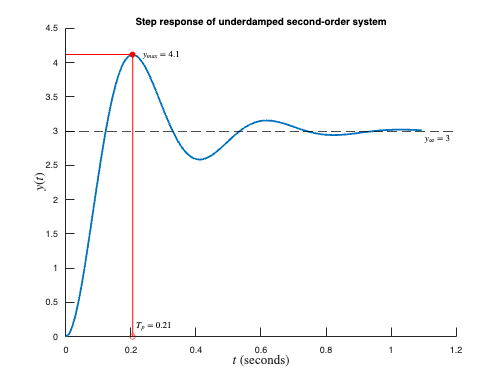

clear
s = tf('s');

K = 3;
zeta = 0.3;
wn = 16;

P = K*wn^2/(s^2+2*zeta*wn*s+wn^2);
[y,t] = step(P);
100*exp(-zeta*pi/sqrt(1-zeta^2));
%y(t)
figure,clf,hold on
plot(t,y,LineWidth=2)
yline(K,'--k',['$y_\infty=$',num2str(K,2)],Interpreter='latex',LabelVerticalAlignment='bottom')

line(pi/(wn*sqrt(1-zeta^2))*[1 1],K*[0 1+exp(-zeta*pi/sqrt(1-zeta^2))],Color='red')
line(pi/(wn*sqrt(1-zeta^2))*[0 1],K*(1+exp(-zeta*pi/sqrt(1-zeta^2)))*[1 1],Color='red')
plot(pi/(wn*sqrt(1-zeta^2)),K*(1+exp(-zeta*pi/sqrt(1-zeta^2))),'ro',MarkerFaceColor='r')
text(pi/(wn*sqrt(1-zeta^2)),K*(1+exp(-zeta*pi/sqrt(1-zeta^2))),['$\quad y_{max}=$',num2str(K*(1+exp(-zeta*pi/sqrt(1-zeta^2))),2)],Interpreter='latex')

plot(pi/(wn*sqrt(1-zeta^2)),0,'ro')
text(pi/(wn*sqrt(1-zeta^2)),0.05*K,['$~T_p=$',num2str(pi/(wn*sqrt(1-zeta^2)),2)],Interpreter='latex')

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)
title('Step response of underdamped second-order system')

% axis tight

### 6.5.4 Percentage overshoot

**Percentage overshoot, **$\%OS$, is defined as the amount that the response overshoots the steady-state value, $y_{\infty}$, at the peak time $T_p$. This quantity is expressed as a percentage of the steady-state value.

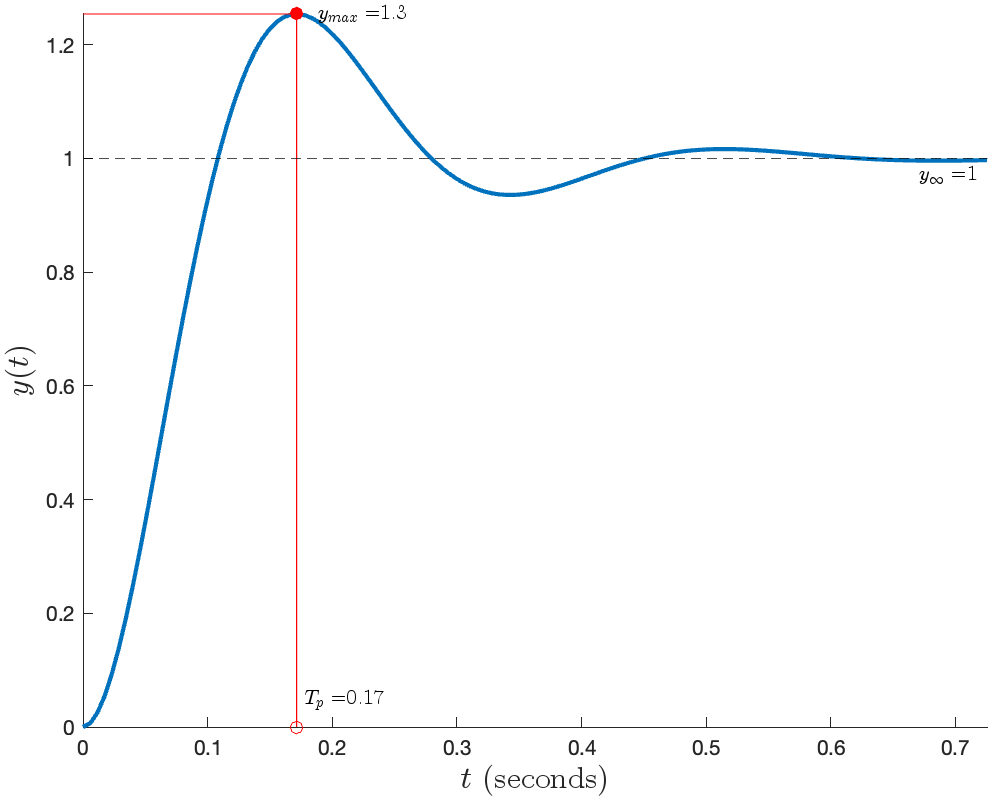

**Figure 6.7:** Step response of second-order system, showing overshoot relative to steady-state value.

With reference to the figure above, the percent overshoot is defined as

$\%OS=100\frac{y_{max}-y_{\infty}}{y_{\infty}}$,

where $y_{max}=y(T_p)$. That is, the maximum value of $y(t)$ corresponds with the peak time that we determined in the previous section of

$\begin{array}{ll} 
y_{max}
&= 1+e^{-\zeta\pi/\sqrt{1-\zeta^2}
\end{array}
$.

Assuming the input signal is a unit step, $u(t)=1$, the corresponding final value will be $y_{\infty}=A_s=1$. The percentage overshoot formula follows as

$\%OS=100e^{-\zeta\pi/\sqrt{1-\zeta^2}$.

Note that this result generalises for any value of $K$. We can visualise the relationship between damping ratio and percent overshoot of an underdamped second-order system using the code below.

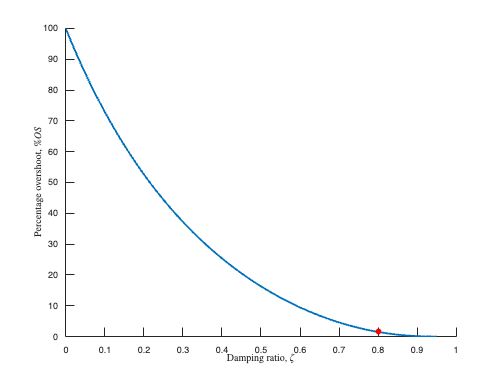

clear

zeta = linspace(0,.95,100);
OS = 100*exp(-zeta.*pi./sqrt(1-zeta.^2));

zeta_ = 0.8;
OS_ = 100*exp(-zeta_*pi/sqrt(1-zeta_^2));

figure,clf,hold on
plot(zeta,OS,LineWidth=2)
plot(zeta_,OS_,'ro',MarkerFaceColor='r')
xlabel('Damping ratio, $\zeta$',Interpreter='latex')
ylabel('Percentage overshoot, $\% OS$',Interpreter='latex')

Note that only $\zeta$ affects the overshoot parameter, not $\omega_n$. We can also determine the required damping ratio if we are given (or can measure) the percent overshoot, by solving the $\%OS$ equation for $\zeta$, namely

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}$.

This is useful if we are tasked with determining the damping ratio of an unknown transfer function using step response data.

### 6.5.5 Settling time

**Settling time** is the time it takes for the output response to enter and stay within $2\%$ of the steady-state value, $y_\infty$. Based on this, we set the amplitude of the decaying sinusoid to $0.02$:

$e^{-\zeta\omega_n t}\frac{1}{\sqrt{1-\zeta^2}}=0.02$.

Note that this is a conservative approximation, as we are assuming that the sinusoid experiences a peak at this time point ($\cos(\omega_n\sqrt{1-\zeta^2}t-\phi)=1$). Solving the equation above for $t$ yields

$T_s=\frac{-\ln\left(0.02\sqrt{1-\zeta^2}\right)}{\zeta\omega_n}\approx \frac{4}{\zeta\omega_n}$.

clear
s = tf('s');

K = 5;
zeta = 0.2;
wn = 23;

P = K*wn^2/(s^2+2*zeta*wn*s+wn^2)


P =
 
        2645
  -----------------
  s^2 + 9.2 s + 529
 
Continuous-time transfer function.
Model Properties


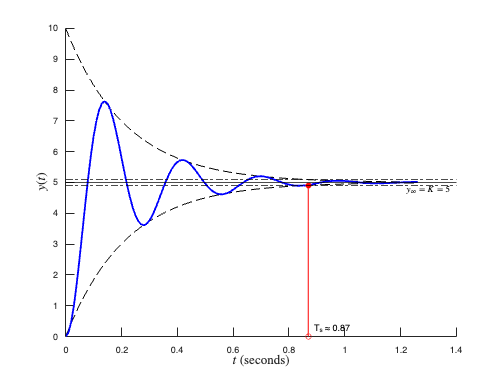

[y,t] = step(P);

ea = K*(1+exp(-zeta*wn*t));
eb = K*(1-exp(-zeta*wn*t));

figure,clf,hold on
plot(t,ea,Color='black',LineStyle='--')
plot(t,eb,Color='black',LineStyle='--')

plot(t,y,'-b',LineWidth=2)
yline(K,'-k',['$y_\infty=K=$',num2str(K,2)],Interpreter='latex',LabelVerticalAlignment='bottom')

yline(.98*K,'k-.')
yline(1.02*K,'k-.')

line(4/(zeta*wn)*[1 1],.98*K*[0 1],Color='red')
plot(4/(zeta*wn),.98*K,'ro',MarkerFaceColor='r')
text(4/(zeta*wn),0.05*K,[' T_s\approx',num2str(4/(zeta*wn),2)])
plot(4/(zeta*wn),0,'ro')

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)

### 6.5.6 Pole locations

We now have expressions that relate peak time, percent overshoot, and settling time to the natural frequency and the damping ratio. Now let us relate these quantities to the location of the poles that generate these characteristics.

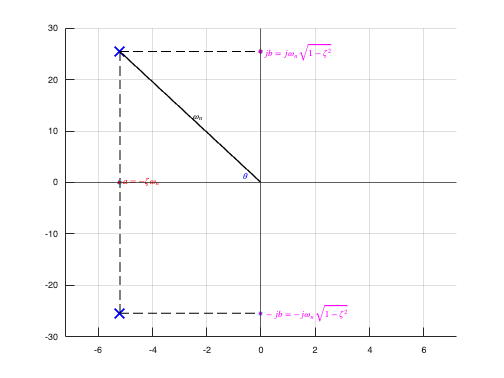

clear
K = 1;
zeta = 0.2;
wn = 26;

b = wn*sqrt(1-zeta^2);
a = -zeta*wn;

p1 = a+1i*b;
p2 = a-1i*b;

figure,clf,hold on,grid on
xline(0),yline(0)
plot(real(p1),imag(p1),'bx',real(p2),imag(p2),'bx',lineWidth=2,MarkerSize=15)


line([a 0],b*[1 1],'Color','black','LineStyle','--')
text(0,b,'$~jb=j\omega_n\sqrt{1-\zeta^2}$',Interpreter='latex',Color='m')
plot(0,b,'o',MarkerFaceColor='m',MarkerSize=4)
line([a 0],-b*[1 1],'Color','black','LineStyle','--')
text(0,-b,'$~-jb=-j\omega_n\sqrt{1-\zeta^2}$',Interpreter='latex',Color='m')
plot(0,-b,'o',MarkerFaceColor='m',MarkerSize=4)
text(.15*a,.05*b,'$~\theta$',Interpreter='latex',Color='blue')
line(a*[1 1],b*[-1 1],'LineStyle','--','Color','k')
plot(a,0,'o',MarkerFaceColor='r',MarkerSize=4)
text(a,0,'$~a=-\zeta\omega_n$',Interpreter='latex',Color='r')
line([0 a],[0,b],'Color','k','LineWidth',1.5)
text(a/2,b/2,'$~\omega_n$',Interpreter='latex')
xlim([a-2 -a+2])

% axis equal

Ts=num2str(4/(zeta*wn))

Ts = '0.76923'

OS_ = 100*exp(-zeta*pi/sqrt(1-zeta^2))

OS_ = 52.6621

t_p=pi/(wn*sqrt(1-zeta^2))

t_p = 0.1233

y_max=K*(1+exp(-zeta*pi/sqrt(1-zeta^2)))

y_max = 1.5266




T_pp=pi/b

T_pp = 0.1233

T_ss=4/a

T_ss = -0.7692

Recall that we can specify our two underdamped poles as

$p_{1,2}=a\pm jb$.

Consulting the s-plane, we see that $\omega_n=\sqrt{a^2+b^2}$ based on Pythagoras' theorem. Based on this, the angle that subtends the vector from the origin to $p_1$ to the real axis is given by

$\theta = \cos^{-1}\frac{\zeta\omega_n}{\omega_n}=\cos^{-1}\zeta$.

Therefore, the damping ratio can be obtained from the pole-zero map of $P(s)$ by

$\zeta=\cos\theta$.

This aligns with our understanding of system types, as a critically damped system will have a damping ratio of $\zeta=1$ (implying $\theta=0$), and an undamped system will have a damping ratio of $\zeta=0$ (implying $\theta=\frac{\pi}{2}$). Consulting our $\%OS$ formula of

$\%OS=100e^{-\zeta\pi/\sqrt{1-\zeta^2}$,

which is only a function of $\zeta$,this implies that the percentage overshoot will remain unchanged for constant $\theta$, which is equivalent to saying that the ratio of the complex pole's imaginary and real components remains unchanged. 

Additionally, noting that $a=-\zeta\omega_n$ and $b=\omega_n\sqrt{1-\zeta^2}$, we can therefore determine the peak time and settling time using the pole locations as

$T_p=\frac{\pi}{\omega_n\sqrt{1-\zeta^2}}=\frac{\pi}{b}$,

$T_s \approx \frac{4}{\zeta\omega_n}=\frac{4}{|a|}$.

For underdamped systems, we refer to $b$ and $a$ as the *damped frequency of oscillation* and *exponential damped frequency*, respectively. Given the relationships above, we can draw straight lines in the s-plane that correspond to 

- constant peak times (as a result of constant $b$ values),

- constant settling time (as a result of constant $a$ values), and

- constant percentage overshoot (as a result of constant $\zeta=\cos\theta$).

An example is shown in the image below, where $T_{s_2}<T_{s_1}$, $T_{p_2}<T_{p_1}$, and $\%OS_{2}<\%OS_{1}$. Note that this only applies to second-order systems in general.

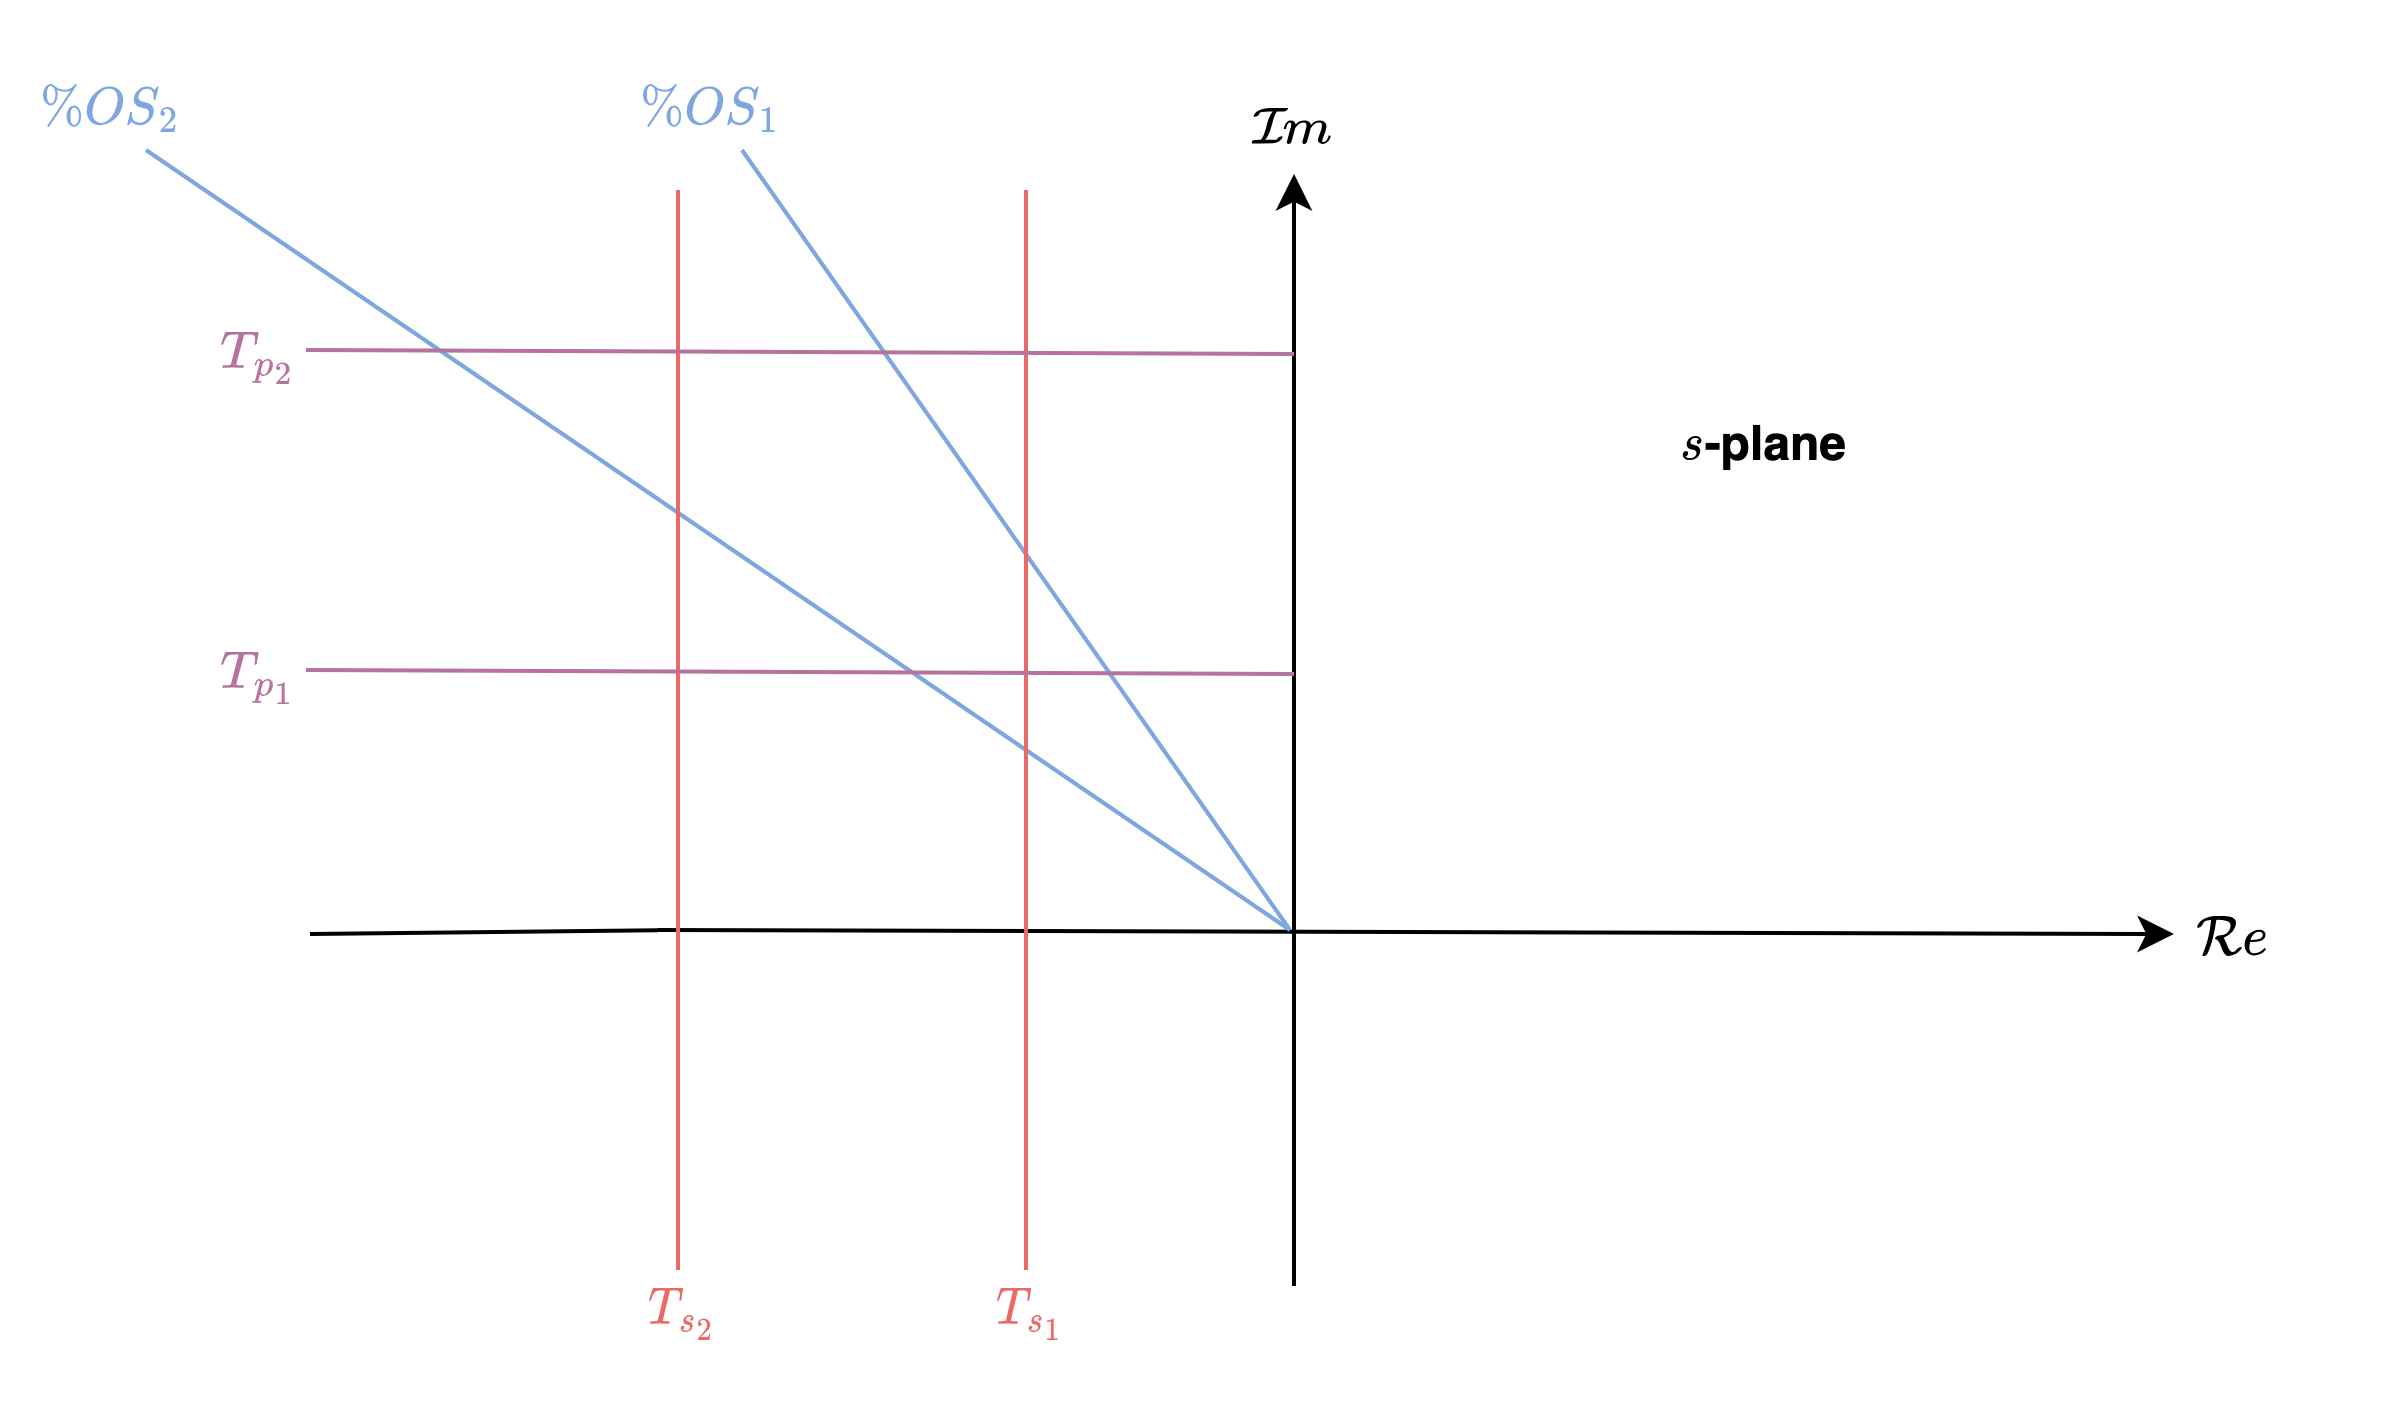

**Figure 6.8:** S-plane showing constant peak, settling, and percentage overshoot lines.

### 6.5.7 Determining the transfer function via testing

Just as we obtained the transfer function of a first-order system experimentally, we can do the same for a system that exhibits a typical underdamped second-order response. Given step response data from $P(s)$, we can measure the percent overshoot and peak time. Using this information, we can then solve for the damping ratio and natural frequency using


$$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}$$


and

$\omega_n=\frac{\pi}{T_p\sqrt{1-\zeta^2}}$,

respectively, which collectively fully describes the denominator of $P(s)$. The plant gain, $K$, can be found, as in the first-order system, by finding the ratio of the steady-state output response, $y_\infty$, and value of the input step, $u(t)=\beta$, namely

$K=\frac{y_\infty}{\beta}$.

## 6.6 System response with additional poles

So far, we have only analyzed systems with one or two poles. It must be emphasized that the formulas describing percent overshoot, settling time, and peak time were derived only for a system with two complex poles and no zeros. If a system has more than two poles or has zeros, we cannot use the formulas to calculate the performance specifications that we derived. However, under certain conditions, a system with more than two poles or with zeros can be *approximated* as a second-order system that has just two complex *dominant poles*. Once we justify this approximation, the formulas for percent overshoot, settling time, and peak time can be applied to these higher-order systems by using the location of the dominant poles.

### 6.6.1 Pole dominance

Given a system with multiple poles, the poles with the smallest real components will inherently result in exponential functions in the time domain with the slowest exponential decay. As a result, these "slow" poles end up *dominating* the output response when the exponential functions of the "faster" poles die out sufficiently fast. We refer to the pole(s) with the smallest real component as the **dominant** **pole(s)**.

### 6.6.2 Three-pole systems

Consider a three-pole system, where two poles are complex conjugates ($p_{1,2}=-\zeta\omega_n\pm \omega_n\sqrt{\zeta^2-1}$), and the third pole is negative-real ($p_3=a_3+j0 < 0$)

$P(s)=\frac{\omega_n^2}{(s^2+2\zeta\omega_n s+\omega_n^2)(s-a_3)} \$.

The corresponding unit step response is


$$\begin{array}{ll}
Y(s) &=\frac{\omega_n^2}{s(s^2+2\zeta\omega_n s+\omega_n^2)(s-a_3)} \\
&= \frac{A}{s}+\frac{B(s+\zeta\omega_n )+C\omega_n}{(s+\zeta\omega_n)^2+\omega_n^2(1-\zeta^2)} + \frac{D}{s-a_3}
\end{array}$$


The time-domain output response follows as 

$y(t)=A+e^{-\zeta\omega_n t}\left[ B\cos(\omega_n t)+C\sin(\omega_n t) \right]+De^{a_3 t}$.

Based on the resulting equation for $y(t)$, a third term, in the form of an exponential function results from the inclusion of an additional pole at $p_3=a_3+j0$. Notably, the frequency of oscillation and exponential decay of the underdamped response remains the same, but the coefficients are different.

### 6.6.3 Model order reduction

If the real pole, $p_3=a_3$, is sufficiently large-negative, relative to the complex conjugate poles, then we can approximate the third-order system as a second-order system

$P(s)=\frac{\omega_n^2}{(s^2+2\zeta\omega_n s+\omega_n^2)(s-a_3)} \approx \frac{-\omega_n^2/a_3}{s^2+2\zeta\omega_n s+\omega_n^2$.

We denote $\hat{P}(s)=\frac{-\omega_n^2/a_3}{s^2+2\zeta\omega_n s+\omega_n^2$ as the second-order approximation, as a result of model order reduction. Note that we needed to capture the effective gain from the real pole when performing the model order reduction. This is because the additional pole will scale the steady-state value of the response by a factor of $-1/\alpha$. This is shown mathematically by first dividing numerator and denominator of $P(s)$ by $-a_3$

$P(s)=\frac{\omega_n^2}{(s^2+2\zeta\omega_n s+\omega_n^2)(s-a_3)} = \frac{-\omega_n^2/a_3}{(s^2+2\zeta\omega_n s+\omega_n^2)(-s/a_3+1)}$.

We can then show that the approximated system converges on the actual system as $a_3$ tends to negative infinity:

$\lim_{a_3\rightarrow -\infty} -a_3 P(s)=\lim_{\alpha\rightarrow -\infty} \frac{\omega_n^2}{(s^2+2\zeta\omega_n s+\omega_n^2)(-s/a_3+1)}= \frac{\omega_n^2}{(s^2+2\zeta\omega_n s+\omega_n^2)}=\lim_{a_3\rightarrow -\infty} -a_3 \hat{P}(s)$.

In order for $\hat{P}(s)=\frac{-\omega_n^2/a_3}{s^2+2\zeta\omega_n s+\omega_n^2$ to be a sufficient approximation, the exponential from the real pole, $e^{a_3 t}$, needs to decay (approach zero) much faster than that of the exponential from the complex poles, $e^{-\zeta\omega_n t}$. In other words, we require $a_3 \ll -\zeta\omega_n$. Under this condition, the real-valued exponential will die out before the peak time, which will not affect the various performance calculations, such as peak time, settling time and percent overshoot. This will result in the following time-domain approximation of

$y(t)=A+e^{-\zeta\omega_n t}\left[ B\cos(\omega_n t)+C\sin(\omega_n t) \right]+De^{a_3 t} \approx -\frac{1}{a_3}\left(A+e^{-\zeta\omega_n t}\left[ B\cos(\omega_n t)+C\sin(\omega_n t) \right]\right)$.

### 6.6.4 Time-domain comparison

We can visually compare the unit step responses of the third-order underdamped system, $P(s)$, and approximated second-order system, $\hat{P}(s)$, using a common unit step input of $U(s)=1/s$, which results in $Y(s)=P(s)U(s)$, and $\hat{Y}(s)=\hat{P}(s)U(s)$, respectively. The code block below generates the two responses.

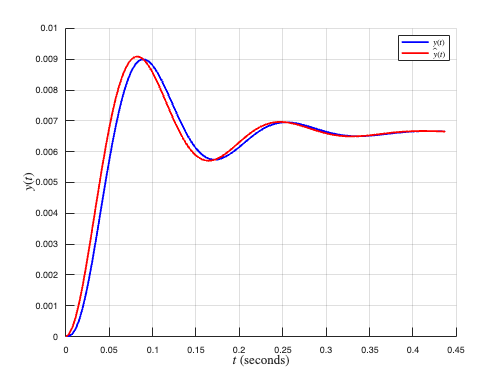

clear
s = tf('s');

K = 1;
zeta = 0.3;
wn = 40;
a_3 = -151; %location of real pole. 

P = K*wn^2/(s^2+2*zeta*wn*s+wn^2)/(s-a_3);    %actual system
P_est = -1/a_3*K*wn^2/(s^2+2*zeta*wn*s+wn^2); %approximated system

[y,t] = step(P);
[y_est,t_est] = step(P_est);

figure,clf,hold on,grid on

plot(t,y,LineWidth=2,Color='blue')
plot(t_est,y_est,LineWidth=2,Color='red')
legend('$y(t)$','$\hat{y}(t)$',interpreter='latex')
% yline(K,'-k',['$A_s=$',num2str(K,2)],Interpreter='latex',LabelVerticalAlignment='bottom')

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)

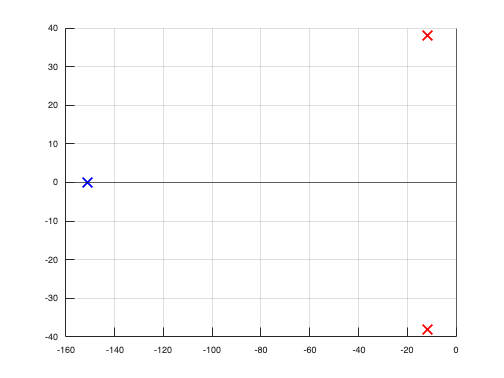


figure,clf,hold on,grid on
xline(0),yline(0)
p1 = -zeta*wn+1i*wn*sqrt(1-zeta^2);
p2 = -zeta*wn-1i*wn*sqrt(1-zeta^2);
plot(real(p1),imag(p1),'rx',real(p2),imag(p2),'rx',MarkerSize=15,lineWidth=2)
p3 = a_3;
plot(real(p3),imag(p3),'bx',MarkerSize=15,lineWidth=2)

The simulation above shows that as $a_3$ becomes increasingly large-negative, the two responses become more similar. The condition of $a_3 \ll -\zeta\omega_n$, implies that the real-valued exponential decay is negligible after five time constants: $e^{5T_ca_3}=e^{-5}=0.0067$. Therefore, as a *rule of thumb*, if the real pole is five times further to the left in the s-plane than the dominant complex poles, namely

$a_3 \leq -5\zeta\omega_n$.

we can then find a suitable second-order approximation of the system. 

## 6.7 System response with zeros

As in the case of the three-pole system, two-pole systems with zeros can be approximated as two-pole systems under the correct pole-dominance conditions.

### 6.7.1 Two-pole-one-zero systems

Consider a second-order, underdamped system with a single real zero of $z=c+j0$:

$P(s)=\frac{\omega_n^2(s-z)}{s^2+2\zeta\omega_n s+\omega_n^2} $.

The unit step response follows as


$$\begin{array}{ll}
Y(s) &=\frac{\omega_n^2(s-z)}{s(s^2+2\zeta\omega_n s+\omega_n^2)} \\
&= \frac{A}{s}+\frac{B(s+\zeta\omega_n )+C\omega_n}{(s+\zeta\omega_n)^2+\omega_n^2(1-\zeta^2)} 
\end{array}$$


The time-domain output response is determined using the inverse Laplace transform: 

$y(t)=A+e^{-\zeta\omega_n t}\left[ B\cos(\omega_n t)+C\sin(\omega_n t) \right]$.

The result of including a zero does not alter the general structure of the time-domain response (still a sum of a step and co-sinusoid with unchanged exponential decay and frequency of oscillations), but the coefficients, $A,B$ and $C$, will be affected, which can cause some interesting transients in the response.

### 6.7.2 Model order reduction

If the real zero is sufficiently large-negative, relative to the complex conjugate poles ($z \ll -\zeta\omega_n$), then we can approximate the actual system as a second-order system

$P(s)=\frac{\omega_n^2(s-z)}{s^2+2\zeta\omega_n s+\omega_n^2} \approx \frac{-z\omega_n^2}{s^2+2\zeta\omega_n s+\omega_n^2}=\hat{P}(s)$.

Note that we needed to capture the effective gain from the real zero when performing the model order reduction. This is because the additional zero will affect the steady-state value of the response by a factor of $-z$. Analogous to the three-pole system, if we represent $P(s)$ as

$P(s)=\frac{\omega_n^2(s-z)}{s^2+2\zeta\omega_n s+\omega_n^2} = \frac{-z\omega_n^2(-s/z+1)}{s^2+2\zeta\omega_n s+\omega_n^2}$,

 we can demonstrate the basis for the approximation

$\lim_{z\rightarrow -\infty} -P(s)/z=\lim_{z \rightarrow -\infty} \frac{\omega_n^2(-s/z+1)}{s^2+2\zeta\omega_n s+\omega_n^2}= \frac{\omega_n^2}{s^2+2\zeta\omega_n s+\omega_n^2}=\lim_{z\rightarrow -\infty} -\hat{P}(s)/z$.

### 6.7.3 Time-domain comparison

We can visually compare the unit step responses of the two-pole-one-zero system, $P(s)$, and approximated two-pole system, $\hat{P}(s)$, using the code block below. Using a common unit step input of $U(s)=1/s$, we can then visualise the inverse Laplace transform of $Y(s)=P(s)U(s)$, and $\hat{Y}(s)=\hat{P}(s)U(s)$.

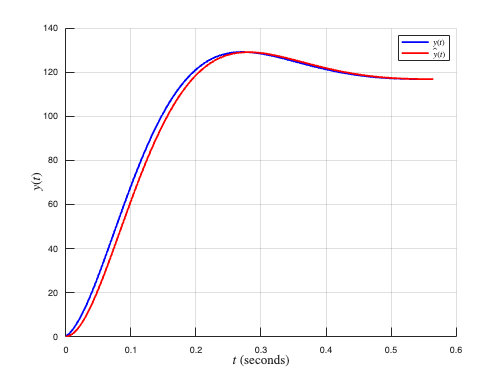

clear
s = tf('s');

K = 1;
zeta = 0.6;
wn = 14;
z = -118;

P = K*wn^2*(s-z)/(s^2+2*zeta*wn*s+wn^2);
P_est = -z*K*wn^2/(s^2+2*zeta*wn*s+wn^2);

[y,t] = step(P);
[y_est,t_est] = step(P_est);

figure,clf,hold on,grid on
plot(t,y,LineWidth=2,Color='blue')
plot(t_est,y_est,LineWidth=2,Color='red')
legend('$y(t)$','$\hat{y}(t)$',interpreter='latex')


xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)

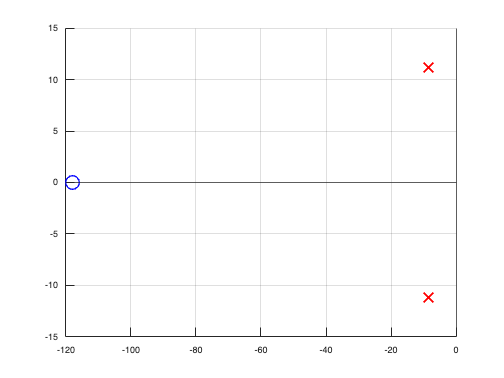


figure,clf,hold on,grid on
xline(0),yline(0)
p1 = -zeta*wn+1i*wn*sqrt(1-zeta^2);
p2 = -zeta*wn-1i*wn*sqrt(1-zeta^2);
plot(real(p1),imag(p1),'rx',real(p2),imag(p2),'rx',MarkerSize=15,lineWidth=2)

plot(real(z),imag(z),'bo',MarkerSize=15,lineWidth=1.5)

### 6.7.4 Leading and lagging responses

One thing you may have noticed is that the addition of a pole makes the response of $P(s)$ more sluggish, relative to the response of $\hat{P}(s)$, whereas the addition of the zero makes the response of $P(s)$ quicker, relative to the second-order approximation. If we define $\hat{P}(s)$ as the second-order approximation of the three-pole-one-zero system $P(s)$, then the relationship between the two systems is simply

$P(s)=(1-s/z)\hat{P}(s)$,

where 

$P(s)=\frac{\omega_n^2(s-z)}{s^2+2\zeta\omega_n s+\omega_n^2} ;\qquad  \hat{P}(s)=\frac{-z\omega_n^2}{s^2+2\zeta\omega_n s+\omega_n^2$.

By extension, the relationship between the corresponding output responses is

 $Y(s)=(1-s/z)\hat{Y}(s)=\hat{Y}(s)-s\hat{Y}(s)/z$.

Assuming the zero lies in the OLHP ($z<0$), the response of $Y(s)$ is made up of the approximated response, $\hat{Y}(s)$, and the scaled time-derivative of the approximated response, $-s\hat{Y}(s)/z$. We have previously defined our two-pole output approximation as (after scaling by $-z$)


$$\begin{array}{ll} 
\hat{y}(t) 
&= -z \left(1-\frac{1}{\sqrt{1-\zeta^2}}e^{-\zeta\omega_nt}\cos\left(\omega_n\sqrt{1-\zeta^2}t-\phi\right)\right)
\end{array}
$$


and the corresponding time-derivative as

$\dot{\hat{y}}(t)=-z\frac{\omega_n}{\sqrt{1-\zeta^2}}e^{-\zeta\omega_nt}\sin\left(\omega_n\sqrt{1-\zeta^2}t\right)$.

Following from this, and taking the inverse Laplace transform of $Y(s)$ above, we can determine the output response of the two-pole-one-zero system as 

$y(t)=\hat{y}(t)-\dot{\hat{y}}(t)/z$.

Given that $z<0$, both $\hat{y}(t)$ and $-\dot{\hat{y}}(t)/z$ have the same sign initially, and the sum of the two signals causes the actual system response to **lead** the response of the two-pole approximation. The lagging behaviour of the three-pole system (relative to the corresponding approximation) can be thought of in a similar manner, except that instead the relationship is "in the other direction". That is, the two-pole approximation can be formulated by scaling the three-pole system by $(1-s/a_3)$, which causes the three-pole system response to **lag** the approximation.

### 6.7.5 Nonminimum-phase systems

An interesting phenomenon occurs if $z>0$, placing the zero in the ORHP. Consulting the equations above, under these conditions,  $\hat{y}(t)$ and $-\dot{\hat{y}}(t)/z$ will have opposite signs initially. We can visualise this effect below when $z$ is located in the right-half s-plane.

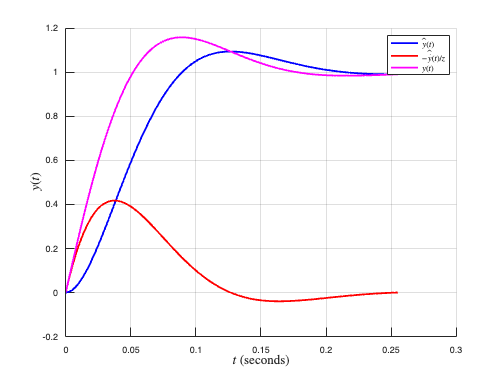

clear 
s = tf('s');

K = 1;
zeta = 0.6;
wn = 31;
z = -37;

P = K*wn^2/(s^2+2*zeta*wn*s+wn^2);
[y_est,t] = step(P);
[dy_est,t] = impulse(P,t);

y = y_est-dy_est/z;

figure,clf,hold on,grid on
plot(t,y_est,LineWidth=2,Color='blue')
plot(t,-dy_est/z,LineWidth=2,Color='red')
plot(t,y,LineWidth=2,Color='magenta')
legend('$\hat{y}(t)$','$-\hat{\dot{y}}(t)/z$','$y(t)$',interpreter='latex')
% yline(K,'-k',['$A_s=$',num2str(K,2)],Interpreter='latex',LabelVerticalAlignment='bottom')

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)

Based on the responses shown above when $z>0$, the time-derivative term, $-\dot{\hat{y}}(t)/z$, acts to initially *drag* the response in the opposite direction of the steady-state value. The resulting response therefore "goes backward before going forwards". A system that exhibits this phenomenon is classed as a **nonminimum-phase **system. This effect becomes less dramatic as $z\rightarrow \infty$, as this results in $-\dot{\hat{y}}(t)/z\rightarrow 0$.

### 6.7.6 Approximate pole-zero cancellation

Consider the system below with one zero and three poles

$P(s)=\frac{K(s-z)}{(s^2+d_1s+d_2)(s-a_3)}$.

If $z=a_3$, we could make use of **pole-zero cancellation** and simplify the system to

$P(s)=\frac{K}{s^2+d_1s+d_2}$.

In reality, poles and zeros do not tend to lie exactly on top of eachother (unless by some type of forced design). However, if the pole and zero are sufficiently close to each other, we can *approximately* cancel the two terms. 

$P(s)=\frac{K(s-z)}{(s^2+d_1s+d_2)(s-a_3)}\approx \frac{K\frac{z}{a_3}}{s^2+d_1s+d_2},~a_3 \approx z$.

Importantly, we would need to capture the effective gain term, $\frac{z}{a_3}$, as before. 